# stabilityFeedbackICB

## Overview

This MATLAB Live Script is associated with the paper "Idiosyncratic choice bias and feedback-induced bias differ in their long-term dynamics".

All data files required to reproduce our results available in [https://github.com/Lior-Lebovich/stabilityFeedbackICB](https://github.com/Lior-Lebovich/stabilityFeedbackICB).

## Contributor

This code was authored by Lior Lebovich, 2024. 

## Datasets

This research includes two studies of Idiosyncratic Choice Biases (ICBs) in human participants.

Each session consisted of 480 trials, 240 vertical and 240 horizontal. In a vertical trial, a vertical line, transected by a horizontal shorter line, was presented on a screen and participants were instructed to indicate which vertical segment out of two is longer. In a horizontal trial, two white Gaussian blur circles were presented on a black screen and participants were instructed to indicate which circle out of two is bigger. Trials in each session were ordered in 160 alternating blocks of 3 horizontal and 3 vertical transected lines. Unbeknown to the participants, there were 40 impossible vertical and 40 impossible horizontal trials in each session, appearing exclusively as first in a block of three trials. Stimuli in the possible trials were uniformly distributed, with an equal number of offsets in each direction.

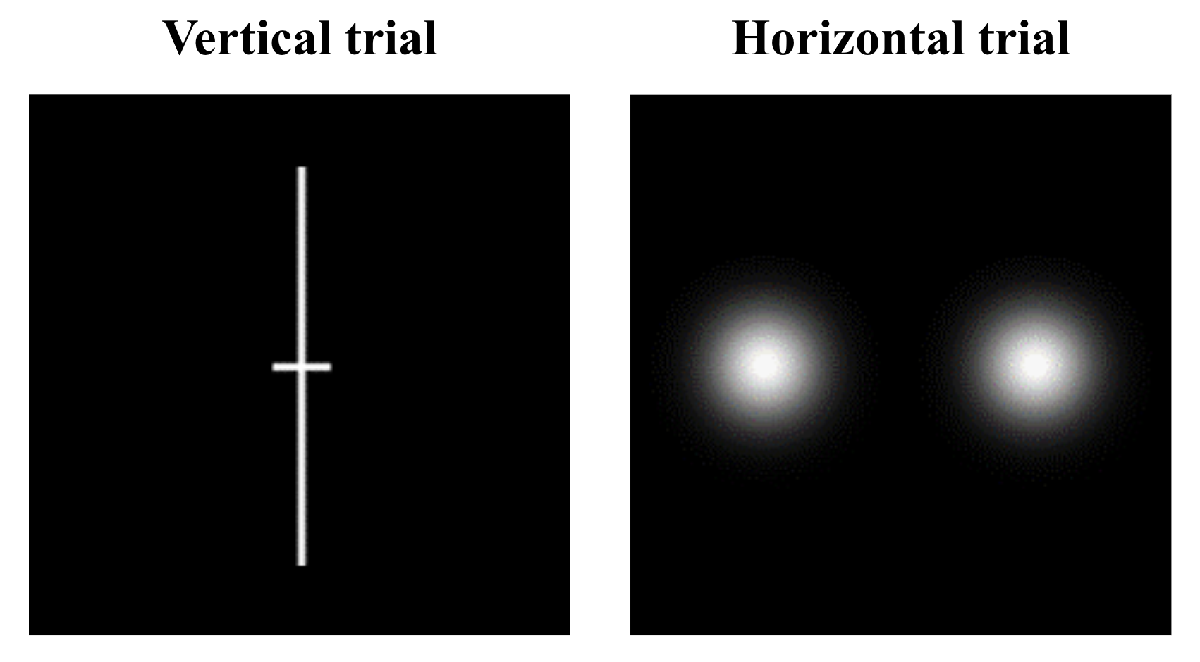

**Stability dataset**: In the first study, participants' ICBs were measured in two repeated experimental sessions that were either 1 hour, 1 day, 1 week, 1 month, 3 months or 8 months apart. A subset of the participants also participated in a third session, 22 months after the second session. No trial-to-trial feedback was provided to participants. There were approx. 30 participants in each delay group. 

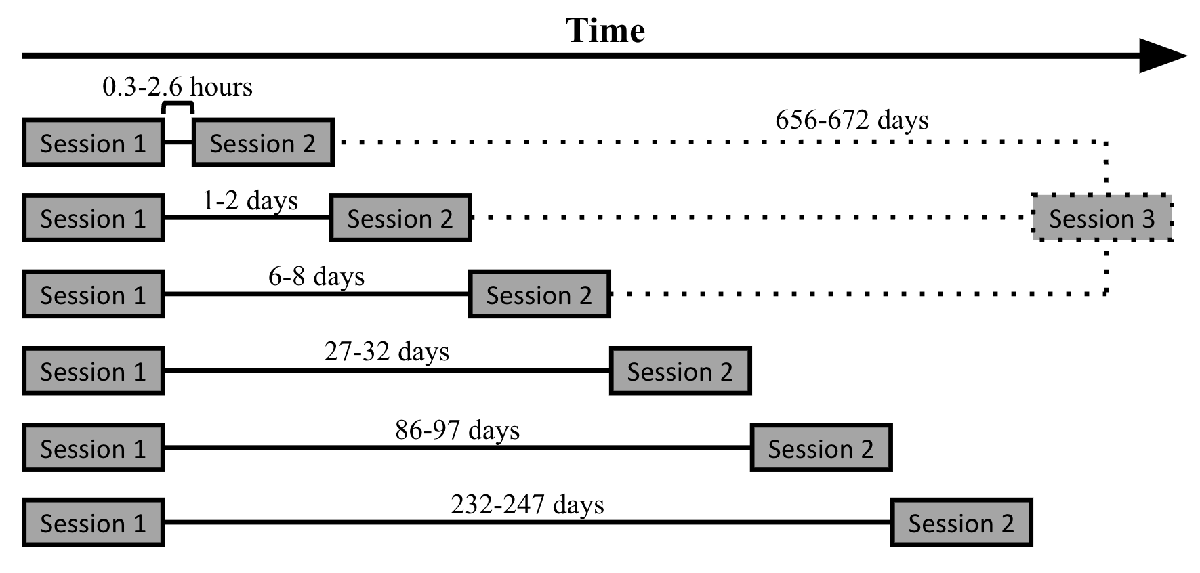

**Feedback dataset**: In the second study, participants' ICBs were measured in three repeated experimental sessions. The first and second sessions were 1 day apart whereas the second and last sessions were either 1 day or 1 month apart. The first and last sessions were as in the sessions in the stability experiment, absent of trial-to-trial feedback, whereas the second session included trial-to-trial feedback. The trial-to-trial feedback was congruent with the stimuli in all possible trials (400/480 of the trials) and biased in the impossible trials (80/480 of the trials). The biased feedback considered one alternative as the correct response in 95% of the impossible trials and the other alternative as the correct response in 5% of the impossible trials. Participants were matched according to their ICBs in the first session and divided 8 groups: 2 second-last sessions delay times X 2 vertical feedback manipulation X 2 horizontal feedback manipulation. 

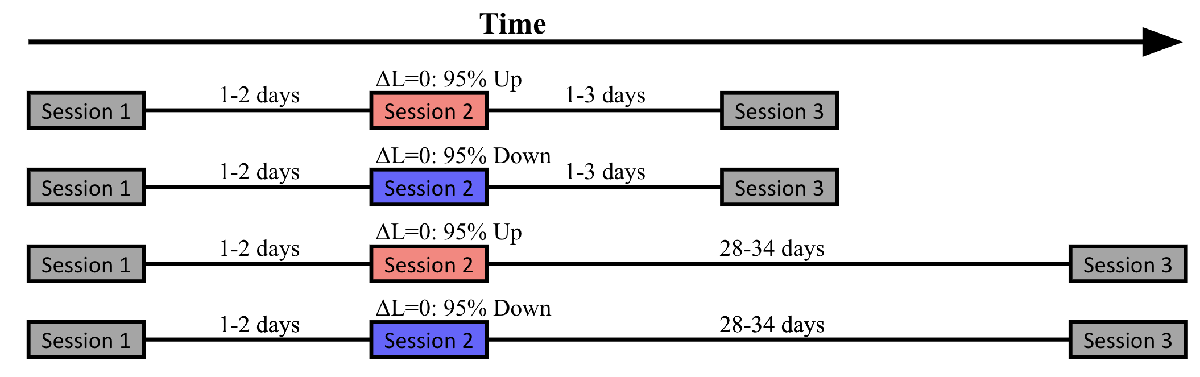

## Main data files:

Main data files are stored by dataset folders.

Response data of each delay group is stored under *[STUDY]/sortedTables/sortedTable_[STUDY]_[DELAY_GROUP].csv*.

Between-sessions hour differences for each delay group are stored under *[STUDY]/assignTables/assignTable_[STUDY]_[DELAY_GROUP].csv*.

Response data of the 8 months delay group in the stability study:

dataName = 'stability';
timeName = 'months8';
dataTable = readtable([dataName '/sortedTables/sortedTable_' ...
    dataName '_' timeName '.csv']);
head(dataTable, 8)

                  ID                        endDate                startDate          didSess3    hourDiff21    hourDiffPrev    session         task         dev    trialNum     rt      response    subj_idx    timeCondition
    ______________________________    ____________________    ____________________    ________    __________    ____________    _______    ______________    ___    ________    _____    ________    ________    _____________

    {'0349843571f5184e8feb7995bc'}    27-Oct-2019 12:16:00    23-Jun-2020 21:

Between-sessions hour differences for the 8 months delay group in the stability study:

dataName = 'stability';
timeName = 'months8';
assignTable = readtable([dataName '/assignTables/assignTable_' ...
    dataName '_' timeName '.csv']);
head(assignTable, 8)

    timeCondition    subj_idx                  ID                  hourDiff21
    _____________    ________    ______________________________    __________

     {'months8'}        0        {'0349843571f5184e8feb7995bc'}      5769.1  
     {'months8'}        1        {'04bf771a158527a584696693ee'}      5791.2  
     {'months8'}        2        {'1e0bedfd7427aa3189a4de3c0c'}      5763.6  
     {'months8'}        3        {'2076262700981aeb117c0457e9'}      5680.4  
     {'months8'}        4        {'21fc1d85a3e4264449ef7f15a9'}      5730.6  
     {'months8'}        5        {'3707663e543822b1143b7f7366'}      5760.1  
     {'months8'}        6        {'3f8ec61536b41cbab72d3b1178'}      5761.2  
     {'months8'}        7        {'47e318f3e1fc694fb0af8efffb'}        5783  



## Read and process experimental data:

Define study (data), task, delay-group names and stimuli deviations:

dataNames = {'stability', 'feedback'};
taskNames = {'Vertical','Horizontal'};
dataTimeGroupNames.feedback = {'day','month'};
dataTimeGroupNames.stability = {'hour','day','week','month','months3',...
    'months8','years'};
dataTimeGroupNames2.stability = {'hour','day','week','month','3 months',...
    '8 months','22 months'};
dataTimeGroupNames2.feedback = dataTimeGroupNames.feedback;
timeStartName.stability = '';
timeStartName.feedback = 'time1';
relFields.stability = {'response'};
relFields.feedback = {'oldResponse','responseCongruent'};
nTrialsDevSessImp = 40;
nTrialsDevSessPos = 20;
devs.stability.Vertical = -10:2:10;
devs.feedback.Vertical = -10:2:10;
devs.stability.Horizontal = -10:2:10;
devs.feedback.Horizontal = -5:1:5;
toNormDev.Vertical = 100;
toNormDev.Horizontal = 75;
nTrialsVect = [20*ones(1,5), 40, 20*ones(1,5)];
xLab.Vertical = '\DeltaL/L';
xLab.Horizontal = '\DeltaR/R';
yLab.Vertical = 'p_{up}';
yLab.Horizontal = 'p_{right}';
save('behavioralDefs.mat');

Note that for the feedback data, the field 'oldResponse' denotes the actual respose (1=up/right and 0=down/left) whereas the field responseCongruent denotes whether the response is congruent(=1) or incungruent(=0) with the feedback manipulation.

Read, compute and store responses, response times and P for each study, delay group, session, task, participant, deviation and manipulation (for feedback data) and read 1st session's demographic data:

for dat = 1:length(dataNames)
    dataName = dataNames{dat};
    timeNames = dataTimeGroupNames.(dataName);
    % read demographic data (provided: 1st session onset):
    demogTable = readtable([dataName '/demogTable/demog_table_' ...
        dataName '.csv']);
    for ti = 1:length(timeNames)
        timeName = timeNames{ti};
        % read resposne data:
        assignTable = readtable([dataName '/assignTables/assignTable_' ...
            dataName '_' timeStartName.(dataName) timeName '.csv']);
        uniIDs = assignTable.ID;
        nSubs = length(uniIDs);
        dataTable = readtable([dataName '/sortedTables/sortedTable_' ...
            dataName '_' timeStartName.(dataName) timeName '.csv']);
        nSessS = max(unique(dataTable.session));

        for task = 1:length(taskNames)
            taskName = taskNames{task};
            % if feedback, then also read the manipulations:
            if strcmp(dataName,'feedback')
                behav.(dataName).(taskName).(timeName).manip = ...
                    assignTable.(['manip' taskName(1:3)]);
            end

            % save demographic data:
            age_cell = cell(nSubs, 1);
            gender_cell = cell(nSubs, 1);
            hand_cell = cell(nSubs, 1);
            for sub = 1:length(uniIDs)
                subID = uniIDs{sub};
                demogSub = demogTable( strcmp( demogTable.ID, subID ) , : );
                age_cell{sub} = demogSub.AgeYears;
                gender_cell{sub} = demogSub.Sex{1};
                hand_cell{sub} = demogSub.Hand{1};
            end
            behav.(dataName).(taskName).(timeName).demog.age = age_cell;
            behav.(dataName).(taskName).(timeName).demog.gender = gender_cell;
            behav.(dataName).(taskName).(timeName).demog.hand = hand_cell;
            behav.(dataName).(taskName).(timeName).demog.ID = uniIDs;

            %
            for dev = devs.(dataName).(taskName)
                if dev == 0
                    nTrialsDev = nTrialsDevSessImp;
                else
                    nTrialsDev = nTrialsDevSessPos;
                end
                if dev < 0
                    devName = ['m' num2str(abs(dev))];
                else 
                    devName = num2str(dev);
                end
                for sess = 1:nSessS
                    tableTaskDevSess = dataTable( strcmp( ...
                        dataTable.task,taskName) & ...
                        (dataTable.dev == dev) & ...
                        (dataTable.session == sess), : );
                    
                    % save RTs:
                    rtMat = nan(nSubs, nTrialsDev);
                    tempMissChs = nan(nSubs, nTrialsDev);
                    for sub = 1:length(uniIDs)
                        subID = uniIDs{sub};
                        rtMat(sub,:) = tableTaskDevSess( strcmp( ...
                            tableTaskDevSess.ID, subID ) , : ).rt';
                        tempMissChs(sub,:) = tableTaskDevSess( strcmp( ...
                            tableTaskDevSess.ID, subID ) , : ...
                            ).(relFields.(dataName){1})';
                    end
                    % omit missing decisions:
                    rtMat( tempMissChs == 999 ) = NaN;
                    
                    behav.(dataName).(taskName).(timeName).(['sess' ...
                        num2str(sess)]).(['dev' devName]...
                        ).rt.mat = rtMat;
                    behav.(dataName).(taskName).(timeName).(['sess' ...
                        num2str(sess)]).(['dev' devName]...
                        ).rt.mean = mean(rtMat,2,'omitnan');
                    
                    % save responses:
                    for f = 1:length(relFields.(dataName))
                        fieldName = relFields.(dataName){f};
                        relMat = nan(nSubs, nTrialsDev);
                        for sub = 1:length(uniIDs)
                            subID = uniIDs{sub};
                            relMat(sub,:) = tableTaskDevSess( strcmp( ...
                                tableTaskDevSess.ID, subID ) , : ).( ...
                                fieldName)';
                        end
                        relMat( isnan(rtMat) ) = NaN; % omit irrelevant/ missing RTs
                        relMat( relMat == 999 ) = NaN; % omit missing decisions
                        behav.(dataName).(taskName).(timeName).(['sess' ...
                            num2str(sess)]).(['dev' devName]...
                            ).(fieldName).mat = relMat;
                        behav.(dataName).(taskName).(timeName).(['sess' ...
                            num2str(sess)]).(['dev' devName]...
                            ).(fieldName).mean = mean(relMat,2,'omitnan');
                    end
                    
                end
            end
        end
    end
end

save('behavioralData.mat','behav');

## Fig. 1 - stability - ICB in the first session:

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

### Compute performance in stability study:

#### Read stability data:

dat = 1;
dataName = dataNames{dat};
timeNames = dataTimeGroupNames.(dataName);
timeNames2 = dataTimeGroupNames2.(dataName);
for task = 1:length(taskNames)
    taskName = taskNames{task};
    lastPar = 0;
    pMat.(taskName) = nan(183,11);
    timeCell = cell(183,1);
    for ti = 1:length(timeNames)-1
        timeName = timeNames{ti};
        timeName2 = timeNames2{ti};
        nSubsTime = length( behav.(dataName).Vertical.(timeName ...
            ).sess1.dev0.response.mean );
        timeCell(lastPar+1:lastPar+nSubsTime) = {timeName2};
        DEV = devs.(dataName).(taskName);
        for d = 1:length(DEV)
            dev = DEV(d);
            if dev < 0
                devName = ['m' num2str(abs(dev))];
            else
                devName = num2str(dev);
            end
            pMat.(taskName)( lastPar+1:lastPar+nSubsTime, d ) = ...
                behav.(dataName).(taskName).(timeName).sess1.(...
                ['dev' devName]).response.mean;
        end
        lastPar = lastPar + nSubsTime;
    end
end

#### Compute performance in vertical task:

Note that performance is measured from possible trials (dev~=0) of the first session.

performanceVertical = 0.5 * ( 1 - mean( pMat.Vertical(:,1:5), 2 ) + ...
    mean( pMat.Vertical(:,7:11), 2 ) );
performanceVertical_avg = mean(100 * performanceVertical)

performanceVertical_avg = 92.0601

performanceVertical_std = std(100 * performanceVertical) 

performanceVertical_std = 5.3114

performanceVertical_minmax = 100 * [min(performanceVertical), ...
    max(performanceVertical)]

performanceVertical_minmax =    62.0000   99.5000


#### Compute performance in horizontal task:

performanceHorizontal = 0.5 * ( 1 - mean( pMat.Horizontal(:,1:5), 2 ) + ...
    mean( pMat.Horizontal(:,7:11), 2 ) );
performanceHorizontal_avg = mean(100 * performanceHorizontal)

performanceHorizontal_avg = 98.5738

performanceHorizontal_std = std(100 * performanceHorizontal) 

performanceHorizontal_std = 1.7894

performanceHorizontal_minmax = 100 * [min(performanceHorizontal), ...
    max(performanceHorizontal)]

performanceHorizontal_minmax =    89.5000  100.0000


### Fig. 1A (&S4A): Psychometric curves of 3 example participants:

Note that different example participants were selected for the vertical and horizontal tasks.

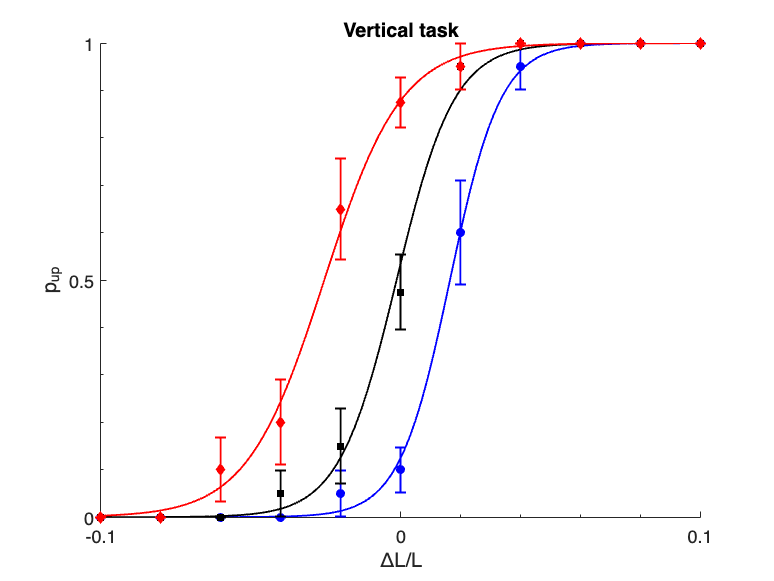

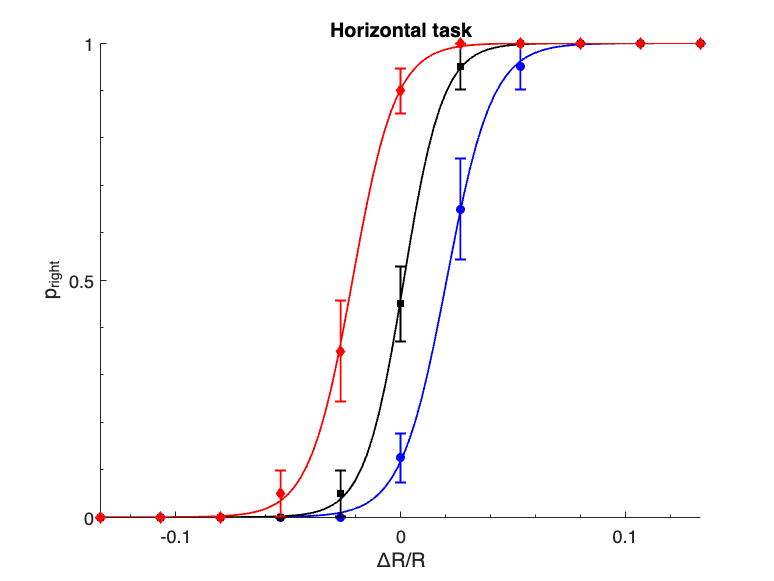

% Define example participants for each task:
subPsycho.Vertical.group = {'months3','month','week'}; 
subPsycho.Vertical.locInGroup = [9,28,22]; 
subPsycho.Vertical.prop_up = nan(1,3);
subPsycho.Horizontal.group = {'week','hour','months8'};
subPsycho.Horizontal.locInGroup  = [8,11,16];
subPsycho.Horizontal.prop_up = nan(1,3);
cols = {'blue', 'black', 'red'};
marks = {'o', 's', 'd'};

% Read raw data of example participants and ML fit logistic curve:
for task = 1:length(taskNames)
    taskName = taskNames{task};
    devVect = devs.(dataName).(taskName) / toNormDev.(taskName);
    if task==1
        figName = 'Figure1A';
    elseif task==2
        figName = 'FigureS4A';
    end
    fig = figure;
    for k = 1:3
        col = cols{k};
        mark = marks{k};
        subGroup = subPsycho.(taskName).group{k};
        subLocInGroup = subPsycho.(taskName).locInGroup(k);
        subID = behav.stability.Vertical.(subGroup).demog.ID{subLocInGroup}; 
        % Read group's raw response data:
        dataTable = readtable([dataName '/sortedTables/sortedTable_' ...
            dataName '_' timeStartName.(dataName) subGroup '.csv']);
        % Read participant's data in session 1 and specific task:
        subTable = dataTable( strcmp(dataTable.ID,subID) & ...
            (dataTable.session==1) & strcmp(dataTable.task,taskName), ...
            {'dev', 'response'} );
        stim = subTable.dev / toNormDev.(taskName); % normalized dev
        response = subTable.response;
        T_sub = table(stim(:), response(:), 'VariableNames', ...
            {'Stim', 'Response'});
        % Fit logistic regression model:
        mdl = fitglm(T_sub, 'Response ~ Stim', 'Distribution', 'binomial');
        % Extract parameters:
        intercept = mdl.Coefficients.Estimate(1);  % b0
        slope = mdl.Coefficients.Estimate(2); 
        % Plot fitted logistic curve:
        x_vals = linspace(min(stim), max(stim), 100);
        y_vals = 1 ./ (1 + exp(-(intercept + slope * x_vals)));
        plot(x_vals, y_vals, col, 'LineWidth', 1); hold on; 
        % Plot empirical data:
        stim_levels = unique(stim);
        prop_up = arrayfun(@(s) mean(response(stim == s)), stim_levels);
        subPsycho.(taskName).prop_up(k) = prop_up(6);
        se_prop = arrayfun(@(s) sqrt(mean(response(stim == s)) * ...
            (1 - mean(response(stim == s))) / sum(stim == s)), stim_levels);
        errorbar( stim_levels, prop_up, se_prop, ...
            'MarkerEdgeColor', 'none', 'MarkerSize', 5, 'Marker', mark, ...
            'LineStyle', 'none', 'lineWidth', 1, 'color', col, ...
            'MarkerFaceColor', col ); hold on;
    end
    xlim([min(stim_levels),max(stim_levels)]); 
    ylim([0,1]); box off; legend off;
    xlabel(xLab.(taskName)); 
    ylabel(yLab.(taskName));
    ggg = gca; 
    ggg.XMinorTick = 'on'; 
    ggg.YMinorTick = 'on';
    xticks(-0.1:0.1:0.1); yticks(0:0.5:1);
    title([taskName ' task']);
    savefig(fig, ['figures/' figName '.fig'])
end

### Fig. 1B (&S4B): ICB (Idiosyncratic Choice Bias) distribution:

The ICB is measured from each participant's reponses in the impossible trials (dev=0).

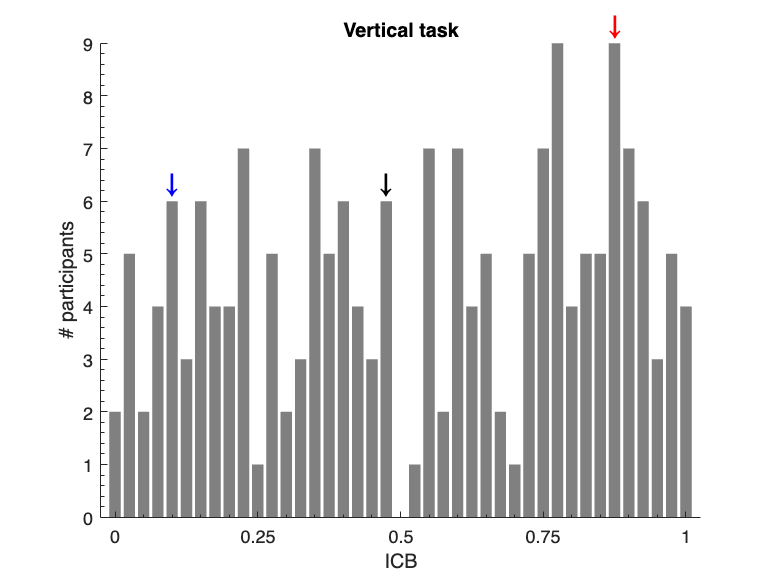

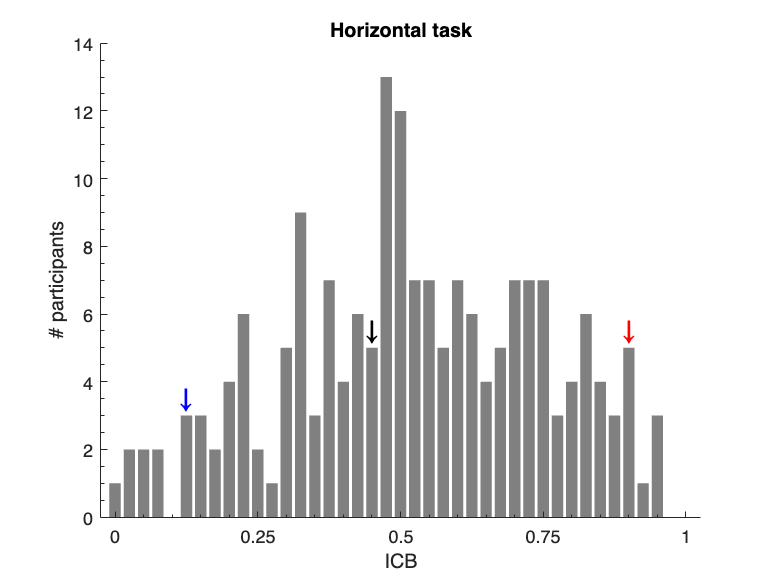

for task = 1:length(taskNames)
    taskName = taskNames{task};
    edges = linspace(0,1,42);
    ICB_BL_pdf = histcounts( pMat.(taskName)(:,6), 'binEdges', edges );
    if task==1
        figName = 'Figure1B';
    elseif task==2
        figName = 'FigureS4B';
    end
    fig = figure;
    bar( 0:(1/40):1, ICB_BL_pdf, 'FaceColor', [.5 .5 .5], 'edgeColor', ...
        'none' ); 
    xlim([-0.025,1.025]); 
    box off; 
    xlabel('ICB'); 
    ylabel('# participants');
    ggg = gca; ggg.XMinorTick = 'on'; ggg.YMinorTick = 'on';
    xticks(0:.25:1); hold on;
    % plot ICBs that correspond to the 3 psychometric curves: 
    for k = 1:3
        col = cols{k};
        ICB_subPsy = subPsycho.(taskName).prop_up(k);
        relatedPDF = ICB_BL_pdf( find( 0:40 == round(40*ICB_subPsy) ) );
        text( ICB_subPsy, relatedPDF, '\downarrow', 'color', col, ...
            'FontSize',15, 'HorizontalAlignment', 'center', ...
            'VerticalAlignment', 'bottom', 'FontWeight', 'bold');
        hold on;
    end
    title([taskName ' task']);
    savefig(fig, ['figures/' figName '.fig'])
end

### Fig. 1C (&S4D): raw vs psychometric fit ICB:

#### Fit psychometric curve of individual participants:

dataNames = {'stability', 'feedback'};
dataTimeGroupNames.feedback = {'day','month'};
dataTimeGroupNames.stability = {'hour','day','week','month','months3',...
    'months8','years'};
dataTimeGroupNames2.stability = {'hour','day','week','month','3 months',...
    '8 months','22 months'};
dataTimeGroupNames2.feedback = dataTimeGroupNames.feedback;
respName.stability = 'response';
respName.feedback = 'oldResponse';
taskNames = {'Vertical','Horizontal'};
toNormDev.Vertical = 100;
toNormDev.Horizontal = 75;
devs.stability.Vertical = -10:2:10;
devs.feedback.Vertical = -10:2:10;
devs.stability.Horizontal = -10:2:10;
devs.feedback.Horizontal = -5:1:5;
numSessions.stability = 2;
numSessions.feedback = 3;

sess = 1;

for dat = 1:numel(dataNames)
    dataName = dataNames{dat};
    timeNames = dataTimeGroupNames.(dataName);
    responseName = respName.(dataName);
    for ti = 1:numel(timeNames)
        timeName = timeNames{ti};
        subIDs = behav.(dataName).Vertical.(timeName).demog.ID;
        numSubsTimeName = size( subIDs, 1 );
        % Read delay group's raw response data:
        dataTable = readtable([dataName '/sortedTables/sortedTable_' ...
            dataName '_' timeStartName.(dataName) timeName '.csv']);
        for task = 1:numel(taskNames)
            taskName = taskNames{task};
            slope_subs = nan(numSubsTimeName,1);
            bias_subs = nan(numSubsTimeName,1);
            p_subDev = nan(numSubsTimeName,11);
            for sub = 1:numSubsTimeName
                subID = subIDs{sub};
                % Read participant's data in session 1 and specific task:
                colNames = {'dev', respName.(dataName)};
                subTable = dataTable( strcmp(dataTable.ID,subID) & ...
                    (dataTable.session==1) & strcmp(dataTable.task,taskName), ...
                    colNames );
                stim = subTable.dev / toNormDev.(taskName); % normalized dev
                response = subTable.(colNames{2});
                T_sub = table(stim(:), response(:), 'VariableNames', ...
                    {'Stim', 'Response'});
                
                % Fit logistic regression model:
                mdl = fitglm(T_sub, 'Response ~ Stim', 'Distribution', 'binomial');
                % Extract parameters:
                bias_subs(sub) = mdl.Coefficients.Estimate(1);  % b0, intercept
                slope_subs(sub) = mdl.Coefficients.Estimate(2); 
                % Also store observed and fit p:
                stim_levels = unique(stim);
                prop = arrayfun(@(s) mean(response(stim == s)), stim_levels);
                p_subDev(sub,:) = prop';
            end
            pStrct.(dataName).(taskName).(timeName).(['sess' ...
                num2str(sess)]) = p_subDev;
            slpStrct.(dataName).(taskName).(timeName).(['sess' ...
                num2str(sess)]) = slope_subs;
            biasStrct.(dataName).(taskName).(timeName).( ...
                ['sess' num2str(sess)]) = bias_subs;
            clear p_subDev slope_subs bias_subs;
        end
    end
end

#### Plot ICB | raw vs ICB | psychometric fit:

stability - Vertical: obs/psychometric fit p0 correlation (1st session):


rho = 0.9846

pval = 5.8464e-139

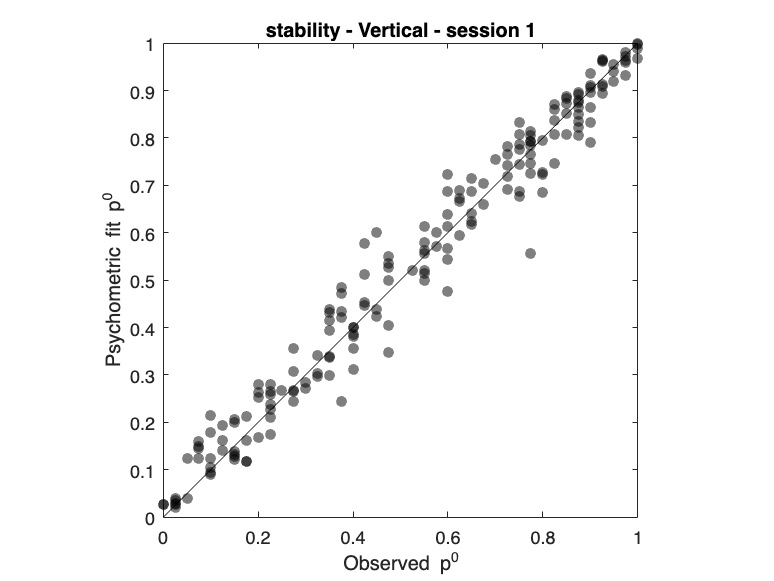

feedback - Vertical: obs/psychometric fit p0 correlation (1st session):


rho = 0.9920

pval = 2.4288e-122

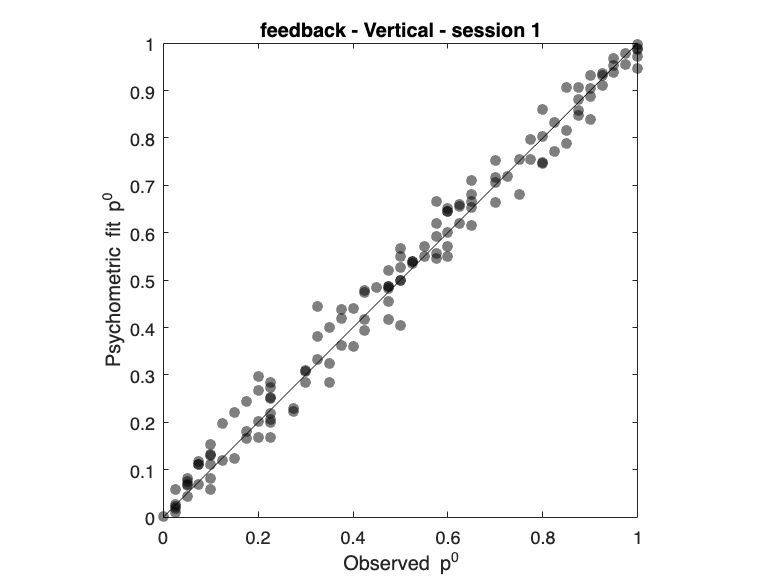

stability - Horizontal: obs/psychometric fit p0 correlation (1st session):


rho = 0.9924

pval = 1.6284e-166

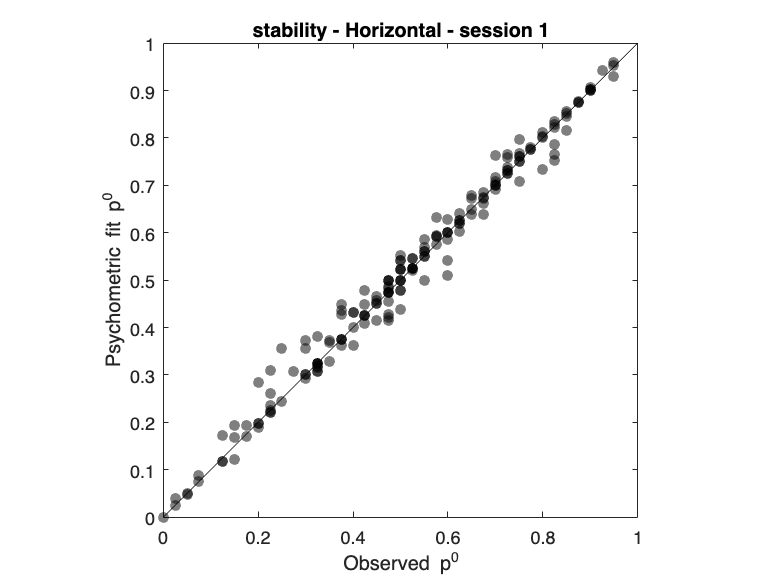

feedback - Horizontal: obs/psychometric fit p0 correlation (1st session):


rho = 0.9816

pval = 3.3357e-98

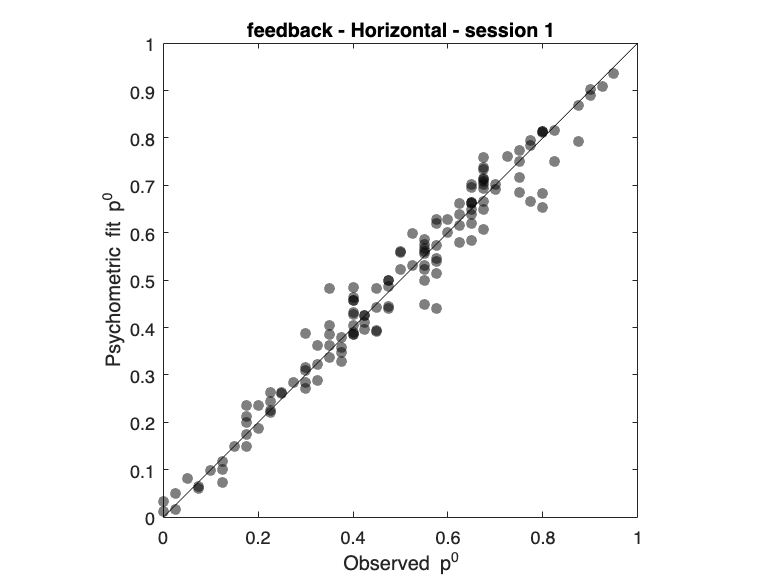

dTimeGroupNames.feedback = {'day','month'};
dTimeGroupNames.stability = {'hour','day','week','month','months3',...
    'months8'};

for task = 1:numel(taskNames)
    taskName = taskNames{task};
    obs_P0_task_cell = cell( numel(dataNames), 1 );
    psyc_P0_task_cell = cell( numel(dataNames), 1 );
    for dat = 1:numel(dataNames)
        dataName = dataNames{dat};
        timeNames = dTimeGroupNames.(dataName);
        responseName = respName.(dataName);
        obs_P0_dat_cell = cell( numel(timeNames), 1 );
        psyc_P0_dat_cell = cell( numel(timeNames), 1 );
        for ti = 1:numel(timeNames)
            timeName = timeNames{ti};
            obs_P0 = pStrct.(dataName).(taskName).(timeName).sess1(:,6);
            slope_subs = slpStrct.(dataName).(taskName).(timeName).sess1;
            bias_subs = biasStrct.(dataName).(taskName).(timeName).sess1;
            psyc_P0 = 1 ./ (1 + exp(-bias_subs));
            obs_P0_dat_cell{ti} = obs_P0;
            psyc_P0_dat_cell{ti} = psyc_P0;
        end
        obs_P0_dat = cell2mat(obs_P0_dat_cell);
        psyc_P0_dat = cell2mat(psyc_P0_dat_cell);

        % Display 1st session ICB raw.psych corr. - by dataset x task:
        disp([dataName ' - ' taskName ...
            ': obs/psychometric fit p0 correlation (1st session):'])
        [rho,pval] = corr( obs_P0_dat, psyc_P0_dat )

        % Plot raw vs psych. ICB:
        fig = figure;
        plot( [0,1], [0,1], 'k-' );
        hold on; 
        scatter( obs_P0_dat, psyc_P0_dat, [], 'k', ...
            'filled', 'MarkerFaceAlpha', .5);
        xlabel('Observed p^0');
        ylabel('Psychometric fit p^0');
        title([dataName ' - ' taskName ' - session 1']);
        axis square;
        if strcmp(dataName,'stability')
            if task==1
                figName = 'Figure1C';
            elseif task==2
                figName = 'FigureS4D';
            end
            savefig(fig, ['figures/' figName '.fig']);
        end
        obs_P0_task_cell{dat} = obs_P0_dat;
        psyc_P0_task_cell{dat} = psyc_P0_dat;
    end
    obs_P0_task = cell2mat( obs_P0_task_cell );
    psyc_P0_task = cell2mat( psyc_P0_task_cell );
    obs_P0_sess1.(taskName) = obs_P0_task;
    psyc_P0_sess1.(taskName) = psyc_P0_task;
end

% Display 1st session ICB raw/psych corr. - by task:
disp('Vertical: obs/psychometric fit p0 correlation (1st session):')

Vertical: obs/psychometric fit p0 correlation (1st session):


[rho,pval] = corr( obs_P0_sess1.Vertical, ...
    psyc_P0_sess1.Vertical )

rho = 0.9878

pval = 3.4099e-258

disp('Horizontal: obs/psychometric fit p0 correlation (1st session):')

Horizontal: obs/psychometric fit p0 correlation (1st session):


[rho,pval] = corr( obs_P0_sess1.Horizontal, ...
    psyc_P0_sess1.Horizontal )

rho = 0.9878

pval = 2.8407e-258

dat = 1;

### Fig. S10: | ICB -.5 | vertical vs horizontal in 1st session - both datasets:

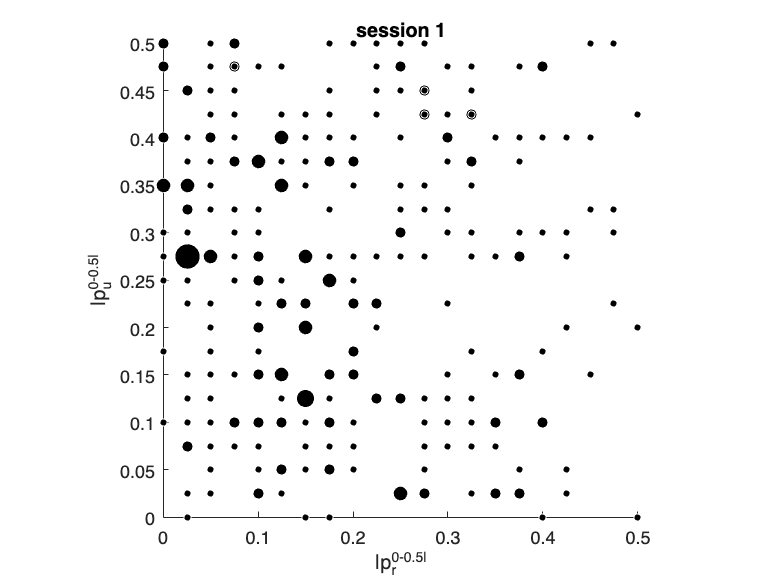

fig = figure;
ICB_hor_all = obs_P0_sess1.Horizontal;
ICB_ver_all = obs_P0_sess1.Vertical;
magICB_hor_all = abs( ICB_hor_all -.5);
magICB_ver_all = abs( ICB_ver_all -.5);
bias_hor_ver_unique = unique( [magICB_hor_all, magICB_ver_all], 'rows' );
all_mSize_check = nan(1, length(bias_hor_ver_unique) );
for i = 1:length(bias_hor_ver_unique)
    mSize = sum( ( magICB_hor_all == bias_hor_ver_unique(i,1) ) .* ...
        ( magICB_ver_all == bias_hor_ver_unique(i,2) ) );
    all_mSize_check(i) = mSize;
    plotDots = plot( bias_hor_ver_unique(i,1), ...
        bias_hor_ver_unique(i,2), ...
        'Marker', 'o', 'MarkerSize', 4+2*(mSize-1), ...
        'MarkerFaceColor', [0,0,0], 'Color', [1 1 1] ); hold on; 
end
xlabel('|p_{r}^0-0.5|');
ylabel('|p_{u}^0-0.5|');
title('session 1');
box off; axis square; 

savefig(fig, 'figures/FigureS10.fig')
% compute corr.:
disp('Horizontal/Vertical obs. p0 correlation (1st session):')

Horizontal/Vertical obs. p0 correlation (1st session):


[rho,pval] = corr( magICB_hor_all, magICB_ver_all )

rho = -0.0419

pval = 0.4556

### Fig. S1 (&S4C): Impossible vs possible ICB:

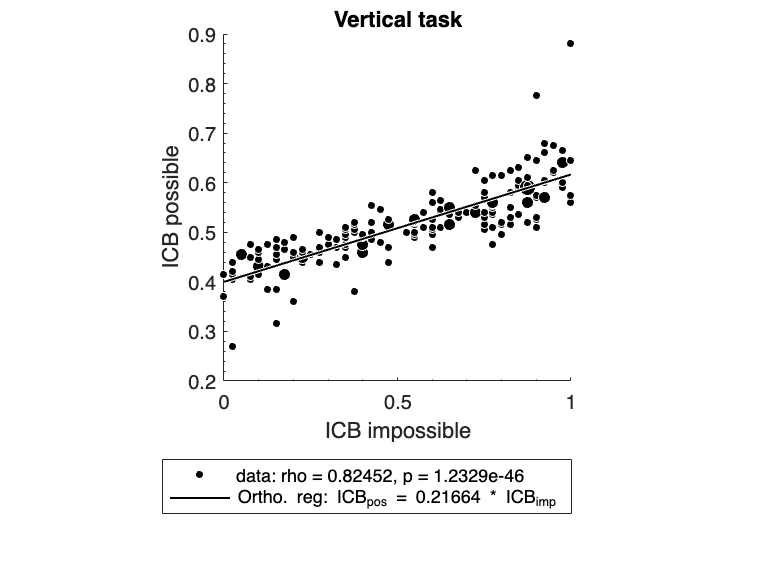

R =     1.0000    0.8245
    0.8245    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.7718
    0.7718    1.0000


RU =     1.0000    0.8660
    0.8660    1.0000


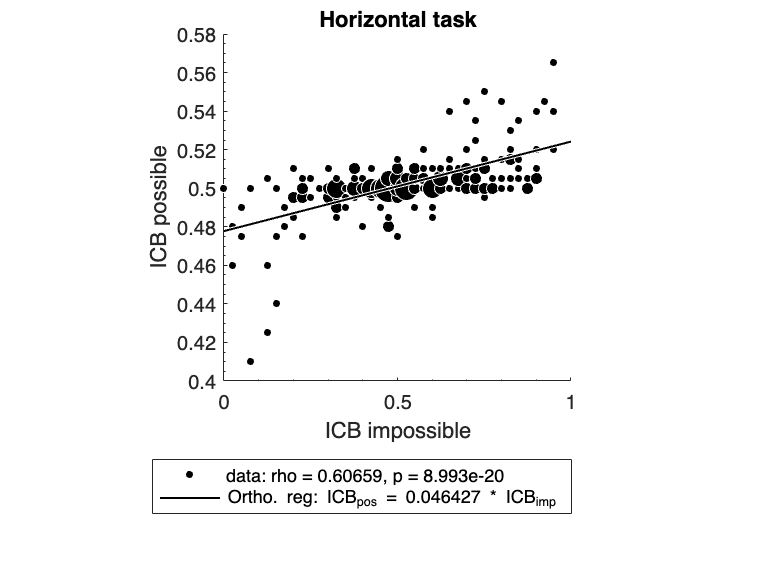

R =     1.0000    0.6066
    0.6066    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.5061
    0.5061    1.0000


RU =     1.0000    0.6909
    0.6909    1.0000


% Extended data Fig. 1 - ICB impossible vs. possible:
for task = 1:length(taskNames)
    taskName = taskNames{task};
    if task==1
        figName = 'FigureS1';
    elseif task==2
        figName = 'FigureS4C';
    end
    fig = figure;
    pPos = mean( pMat.(taskName)(:,[1:5,7:end]), 2 );
    pImp = pMat.(taskName)(:,6);
    bias_imp_pos_unique = unique( [pImp, pPos], 'rows' );
    all_mSize_check = nan(1, length(bias_imp_pos_unique) );
    for i = 1:length(bias_imp_pos_unique)
        mSize = sum( ( pImp == bias_imp_pos_unique(i,1) ) .* ...
            ( pPos == bias_imp_pos_unique(i,2) ) );
        all_mSize_check(i) = mSize;
        plotDots = plot( bias_imp_pos_unique(i,1), ...
            bias_imp_pos_unique(i,2), ...
            'Marker', 'o', 'MarkerSize', 4+2*(mSize-1), ...
            'MarkerFaceColor', [0,0,0], 'Color', [1 1 1] ); hold on; 
    end
    % Orthogonal regression:
    v = pca([pImp pPos]);
    slope = v(2,1)/v(1,1);
    k = mean( pPos ) - slope * mean( pImp );
    plot( [0,1], slope * [0,1] + k, 'Color', [1,1,1], 'lineWidth', 2 ); 
    hold on;
    h = plot( [0,1], slope * [0,1] + k, 'Color', [0,0,0], 'lineWidth', 1 ); 
    hold on;
    mean_imp = mean( pImp );
    mean_pos = mean( pPos );
    sem_imp = std( pImp ) / sqrt( length(pImp) );
    sem_pos = std( pPos ) / sqrt( length(pPos) );
    [rho, pVal] = corr( pImp, pPos );
    legend( [plotDots,h], ['data: rho = ' num2str(rho) ...
        ', p = ' num2str(pVal)], ...
        ['Ortho. reg: ICB_{pos} = ' num2str(slope) ' * ICB_{imp}'], ...
        'Location','SouthOutside');
    xlabel('ICB impossible');
    ylabel('ICB possible')
    box off; axis square; 
    ggg = gca; ggg.XMinorTick = 'on'; ggg.YMinorTick = 'on';   
    title([taskName ' task']);
    savefig(fig, ['figures/' figName '.fig']);
    [R,P,RL,RU] = corrcoef( pImp, pPos, 'Alpha', 0.05 )
end

### Fig. 1 - stabiliy - tests:

Read participants ICBs in the first session:

ICB1 = pMat.Vertical(:,6);

#### Binomial tests for significant ICBs:

Count praticipants with significant ICBs (not corrected for mupltiple comparison) w/ 2-sided binomial tests:

sigBiasesLoc = (myBinomTest( 40*ICB1, 40, .5 ) < .05);
sumSigBias = sum( sigBiasesLoc );
percentSigBias = mean( sigBiasesLoc )

percentSigBias = 0.6885

percentSigUpBias = mean( sigBiasesLoc & (ICB1 > .5) )

percentSigUpBias = 0.3934

percentSigDownBias = mean( sigBiasesLoc & (ICB1 < .5) )

percentSigDownBias = 0.2951

% significant biases correspond to pUp<=0.325(13/40) or pUp>=0.675(27/40):
pdfBinom = pdf('Binomial',0:40,40,0.5);
maximalSigAlpha = sum(pdfBinom(1:14))*2;

**Compute significance for the 3 participants in Fig. 1A:**

pUp_sig_mat = nan(3,2);
for k =1:3
    pUp_sig_mat(k,1) = pMat.Vertical( subPsycho.Vertical(k), 6 );
    pUp_sig_mat(k,2) = myBinomTest( 40 * pUp_sig_mat(k,1), 40, 1/2 );
end
disp('significance for the 3 participants:')

significance for the 3 participants:


pUp_sig_mat

pUp_sig_mat =     0.1000    0.0000
    0.4750    0.8746
    0.8750    0.0000


#### Compute ICB mean absolute deviation:

% MAD ICB:
mad_ICB = mad( ICB1 )

mad_ICB = 0.2633

% mean+-SEM ICB in possible trials:
ICB1pos = mean( pMat.Vertical(:,[1:5,7:end]), 2 );
disp('MAD ICB possible 1st session:')

MAD ICB possible 1st session:


mad( ICB1pos )

ans = 0.0574

#### Compute ICB correlation in im/possible trials:

disp('ICB im/possible correlation 1st session:')

ICB im/possible correlation 1st session:


[cRho, cPValue] = corr( ICB1, ICB1pos )

cRho = 0.8245

cPValue = 1.2329e-46

#### Bootstrap test for global bias:

nSim = 1e6;
nImpossibleTrials = 40; 
sim_avgPup = nan( nSim,1 );
for sim = 1:nSim
    pUp_sim = (1 / nImpossibleTrials) * binornd( nImpossibleTrials, ...
        datasample( ICB1, length(ICB1) )  );
    sim_avgPup(sim) = mean( pUp_sim );
end
disp('bootstrap global bias 1st session:')

bootstrap global bias 1st session:


avgPup_95CI = quantile( sim_avgPup, [.025, 0.975] )

avgPup_95CI =     0.4898    0.5779


#### Bootstrap the standard deviation:

nSim = 1e5;
real_avgPup = mean( ICB1 ); % Bernoulli process with p = average pUp
real_stdPup = std( ICB1 );
sim_stdPup = std( (1 / nImpossibleTrials) * ...
    binornd( nImpossibleTrials, real_avgPup, length(ICB1), nSim  ) );
disp('bootstrap std 1st session:')

bootstrap std 1st session:


sigLevel = sum( sim_stdPup > real_stdPup ) / nSim

sigLevel = 0

#### sig. test ICB dist:

nSim = 1e5;
samp_std = nan( nSim,1 );
bino_std = nan( nSim,1 );
for s = 1:nSim
    samp = datasample( ICB1, length(ICB1) );
    samp_std(s) = std( samp );
    samp_mean = mean(samp);
    bino_std(s) = std( (1 / nImpossibleTrials) * binornd( ...
        nImpossibleTrials, samp_mean, length(ICB1), 1 ) );
end
disp('sig. test ICB dist:')

sig. test ICB dist:


sigLevel = sum( bino_std > samp_std ) / nSim

sigLevel = 0

## Fig. 2 - stabiliy - ICB in the first vs. last session

### Fig. 2B: 8 months delay group

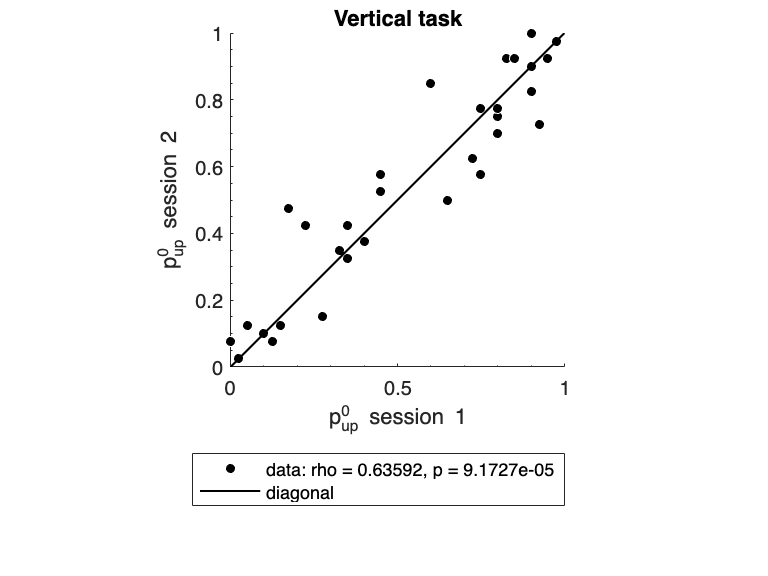

R =     1.0000    0.9275
    0.9275    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.8554
    0.8554    1.0000


RU =     1.0000    0.9643
    0.9643    1.0000


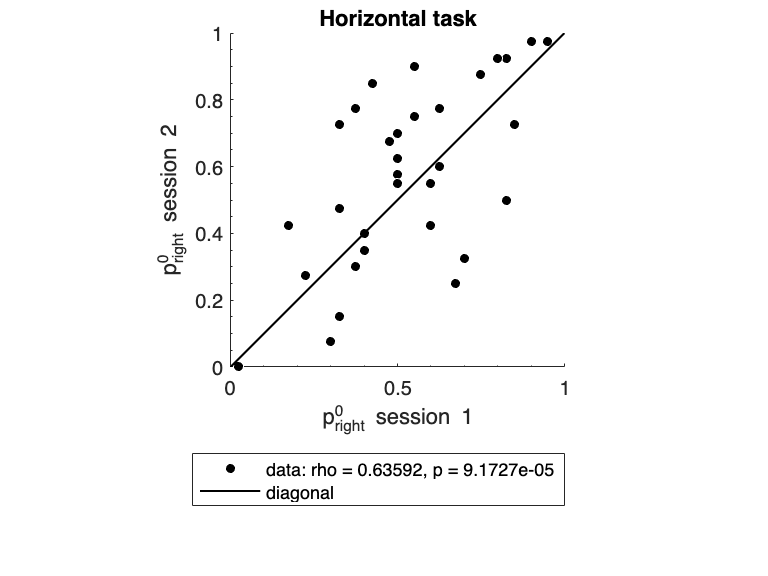

R =     1.0000    0.6359
    0.6359    1.0000


P =     1.0000    0.0001
    0.0001    1.0000


RL =     1.0000    0.3691
    0.3691    1.0000


RU =     1.0000    0.8059
    0.8059    1.0000


dataName = 'stability';
timeName = 'months8';
for task = 1:length(taskNames)
    taskName = taskNames{task};
    fig = figure;
    if task==1
        figName = 'Figure2B';
    elseif task==2
        figName = 'FigureS5A';
    end
    p1 = behav.(dataName).(taskName).(timeName).sess1.dev0.response.mean;
    p2 = behav.(dataName).(taskName).(timeName).sess2.dev0.response.mean;
    plotDots = plot(p1, p2, 'Marker','o','MarkerSize',5, ...
        'MarkerFaceColor', [0,0,0],'Color',[1 1 1]); hold on;
    h = plot( [0,1], [0,1], 'Color', [0,0,0], 'lineWidth', 1 ); 
    hold on;
    legend( [plotDots,h], ['data: rho = ' num2str(rho) ', p = ' ...
        num2str(pVal)], 'diagonal', 'Location','SouthOutside');
    xlabel([yLab.(taskName) '^0 session 1']);
    ylabel([yLab.(taskName) '^0 session 2']);
    box off; axis square; xlim([0,1]); ylim([0,1]);
    ggg = gca; ggg.XMinorTick = 'on'; ggg.YMinorTick = 'on'; 
    title([taskName ' task']);
    [R,P,RL,RU] = corrcoef( p1, p2, 'Alpha', 0.05 )
    savefig(fig, ['figures/' figName '.fig']);
end

### Fig. S2A-F (&S5A): all other groups

Vertical - hour: 


R =     1.0000    0.8078
    0.8078    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.6269
    0.6269    1.0000


RU =     1.0000    0.9060
    0.9060    1.0000


Vertical - day: 


R =     1.0000    0.7757
    0.7757    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.5853
    0.5853    1.0000


RU =     1.0000    0.8850
    0.8850    1.0000


Vertical - week: 


R =     1.0000    0.8188
    0.8188    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.6370
    0.6370    1.0000


RU =     1.0000    0.9143
    0.9143    1.0000


Vertical - month: 


R =     1.0000    0.8443
    0.8443    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.7055
    0.7055    1.0000


RU =     1.0000    0.9207
    0.9207    1.0000


Vertical - 3 months: 


R =     1.0000    0.7323
    0.7323    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.5054
    0.5054    1.0000


RU =     1.0000    0.8645
    0.8645    1.0000


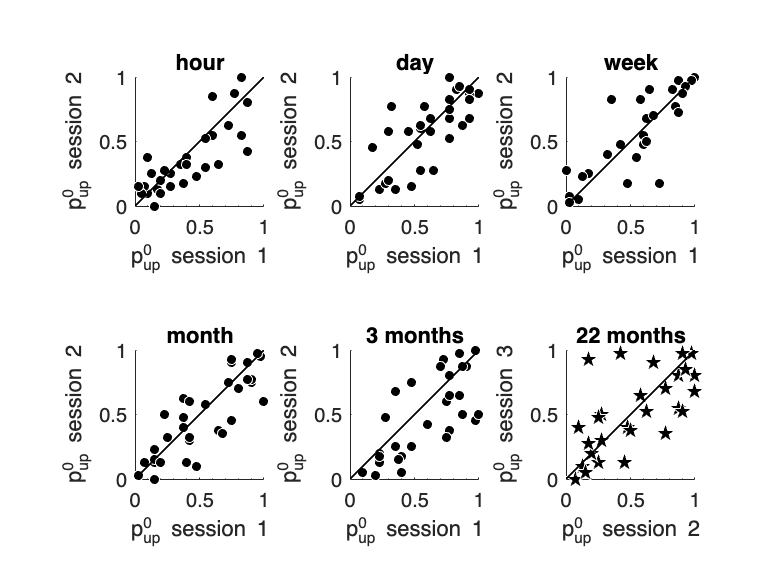

Vertical - 22 months: 


R =     1.0000    0.6699
    0.6699    1.0000


P =     1.0000    0.0001
    0.0001    1.0000


RL =     1.0000    0.4022
    0.4022    1.0000


RU =     1.0000    0.8321
    0.8321    1.0000


Horizontal - hour: 


R =     1.0000    0.7768
    0.7768    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.5735
    0.5735    1.0000


RU =     1.0000    0.8899
    0.8899    1.0000


Horizontal - day: 


R =     1.0000    0.8711
    0.8711    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.7503
    0.7503    1.0000


RU =     1.0000    0.9356
    0.9356    1.0000


Horizontal - week: 


R =     1.0000    0.8024
    0.8024    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.6077
    0.6077    1.0000


RU =     1.0000    0.9061
    0.9061    1.0000


Horizontal - month: 


R =     1.0000    0.7238
    0.7238    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.5063
    0.5063    1.0000


RU =     1.0000    0.8547
    0.8547    1.0000


Horizontal - 3 months: 


R =     1.0000    0.5764
    0.5764    1.0000


P =     1.0000    0.0009
    0.0009    1.0000


RL =     1.0000    0.2728
    0.2728    1.0000


RU =     1.0000    0.7756
    0.7756    1.0000


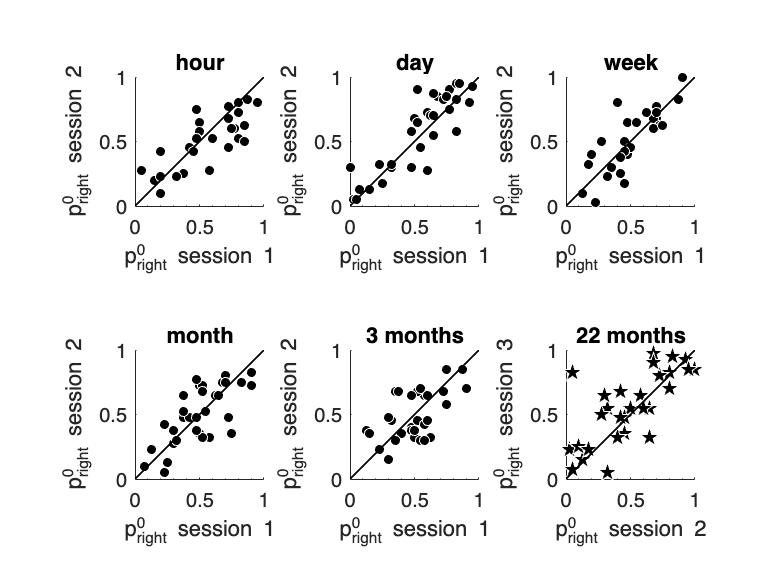

Horizontal - 22 months: 


R =     1.0000    0.7201
    0.7201    1.0000


P =     1.0000    0.0000
    0.0000    1.0000


RL =     1.0000    0.4803
    0.4803    1.0000


RU =     1.0000    0.8597
    0.8597    1.0000


timeNames = dataTimeGroupNames.stability( ...
    ~strcmp( dataTimeGroupNames.stability, 'months8' ) );
timeNames2 = dataTimeGroupNames2.stability( ...
    ~strcmp( dataTimeGroupNames.stability, 'months8' ) );
for task = 1:length(taskNames)
    taskName = taskNames{task};
    fig = figure;
    if task==1
        figName = 'FigureS2';
    elseif task==2
        figName = 'FigureS5A2';
    end
    for ti = 1:length(timeNames)
        timeName = timeNames{ti};
        timeName2 = timeNames2{ti};
        subplot(2,3,ti);
        if strcmp(timeName,'years')
            sessA = '2';
            sessB = '3';
            mark = 'Pentagram';
            markSize = 10;
        else
            sessA = '1';
            sessB = '2';
            mark = 'o';
            markSize = 5;
        end
        pA = behav.stability.(taskName).(timeName).sess1.dev0.response.mean;
        pB = behav.stability.(taskName).(timeName).sess2.dev0.response.mean;
        plot(pA, pB, 'Marker',mark,'MarkerSize',markSize, ...
            'MarkerFaceColor', [0,0,0],'Color',[1 1 1]); hold on;
        plot( [0,1], [0,1], 'Color', [0,0,0], 'lineWidth', 1 ); 
        xlabel([yLab.(taskName) '^0 session ' sessA]);
        ylabel([yLab.(taskName) '^0 session ' sessB])
        title(timeName2);
        box off; axis square; xlim([0,1]); ylim([0,1]);
        ggg = gca; ggg.XMinorTick = 'on'; ggg.YMinorTick = 'on';
        disp([taskName ' - ' timeName2 ': ']);
        [R,P,RL,RU] = corrcoef( pA, pB, 'Alpha', 0.05 )
        savefig(fig, ['figures/' figName '.fig']);
    end

end

### Fig. 2B - stabiliy - tests:

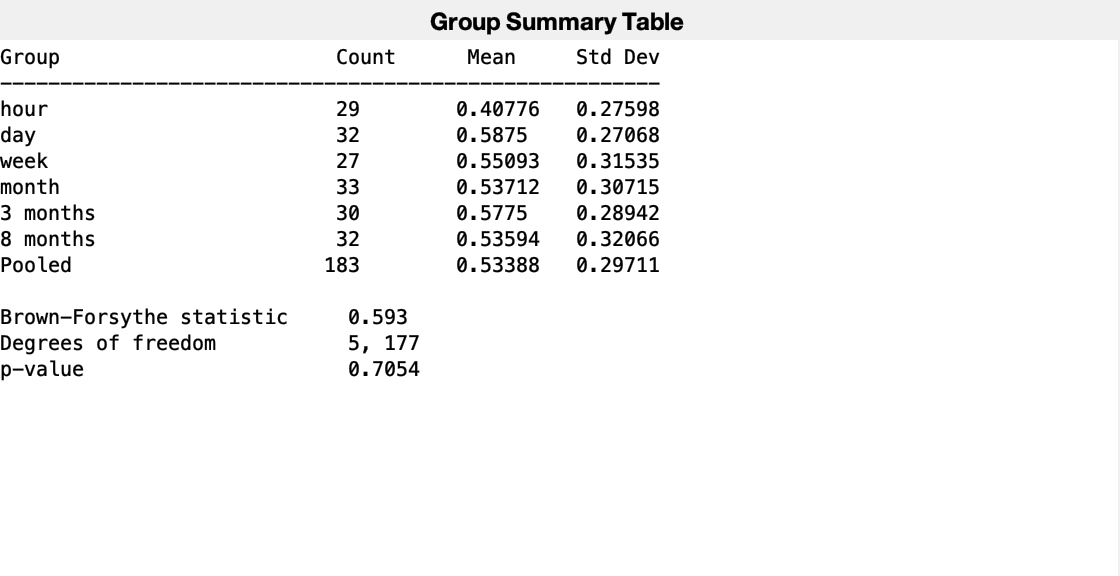

p = 0.7054

% Figure 2 tests (differences between means or variance in the first sess):
% Figure S2-2: Also, plot the summary of comparisons:
% Brown-Forsythe test computed by performing ANOVA on the absolute 
% deviations of the data values from the group medians:
figure;
p = vartestn( pMat.Vertical(:,6), timeCell, 'TestType', 'BrownForsythe' )

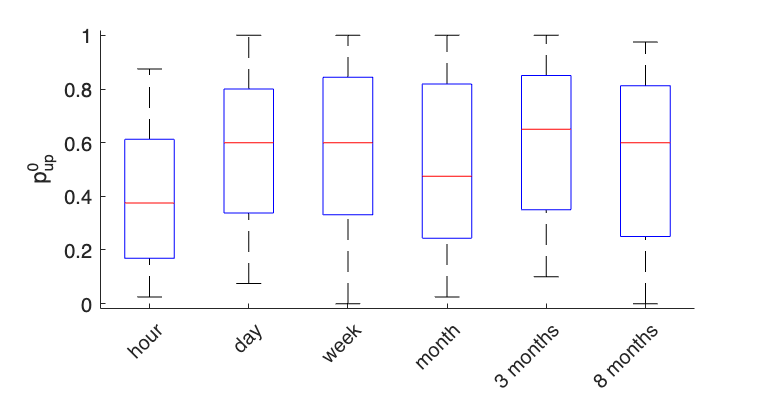

xtickangle(45); ylim([-.02,1.02]); ylabel('p_{up}^0'); box off;

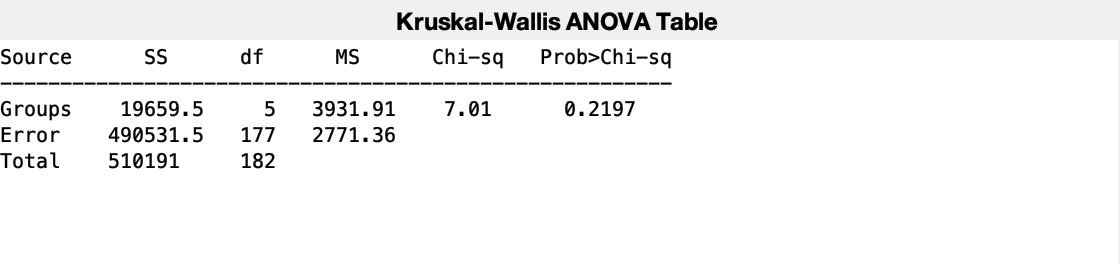

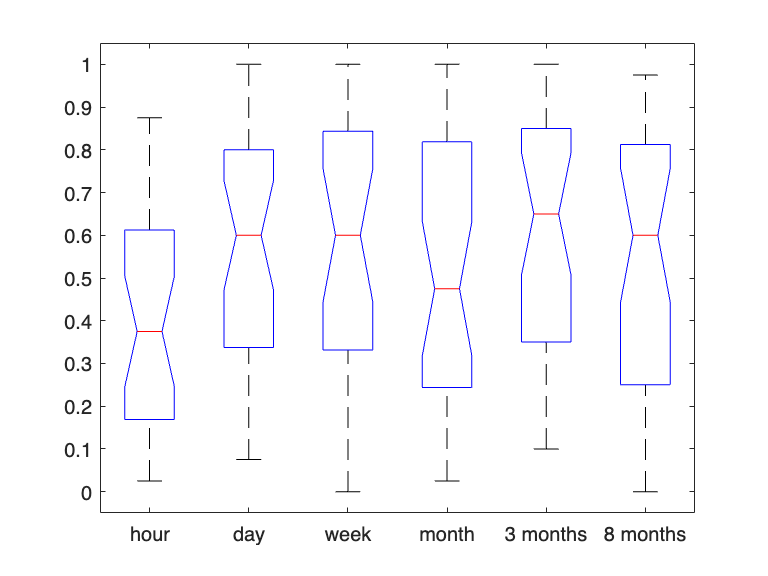

p = 0.2197

stats = struct with fields:
       gnames: {6×1 cell}
            n: [29 32 27 33 30 32]
       source: 'kruskalwallis'
    meanranks: [69.2586 101.0938 94.9444 93.2121 99.5667 92.6875]
         sumt: 6012


% one-way ANOVA of ranks:
figure;
[p,~,stats] = kruskalwallis( pMat.Vertical(:,6), timeCell )

### Fig. 2C (&S5B) - stability - ICB correlation across sessions and tests:

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

#### Compute delay-group between session ICB correlation and 95% CI's:

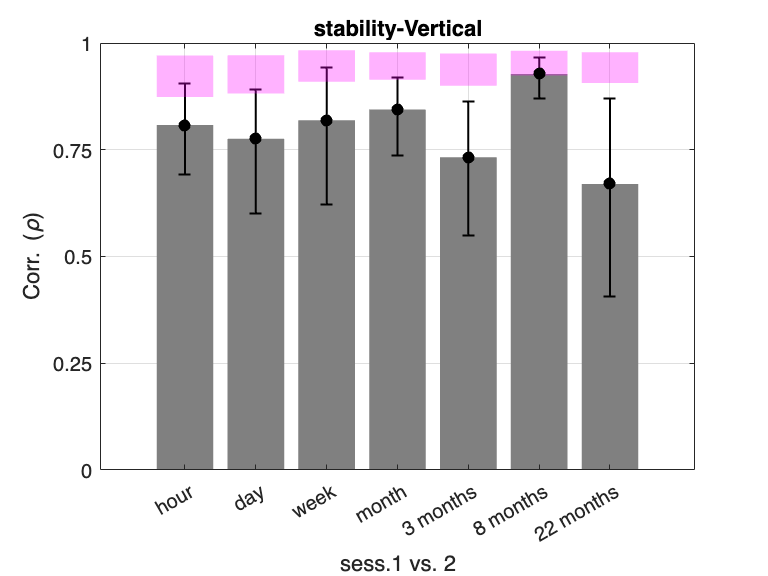

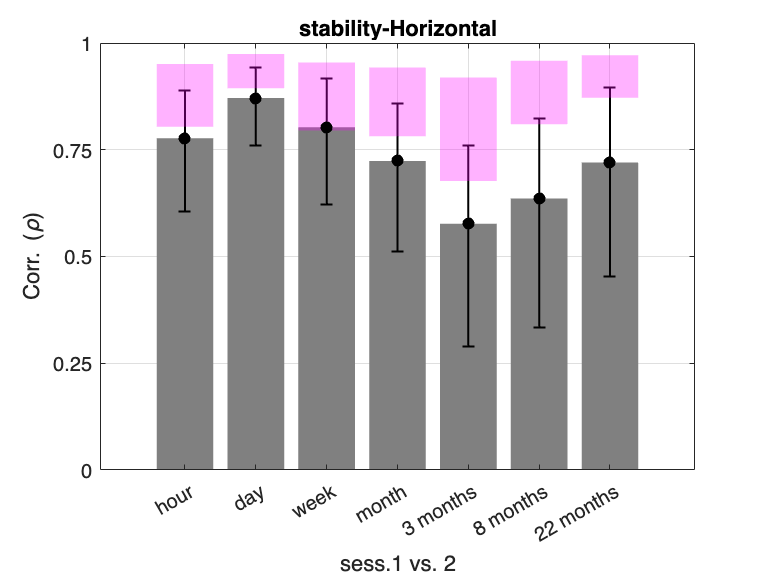

choiceFields.stability = 'response';
nLastSess.stability = 2;
nComps.stability = 1;
nSims = 1e5;
dataName = 'stability';

% read mean days between sessions:
deltaTimeTable = readtable('stability_deltaTime1stLast.csv');
addTimeName = '';
timeNames = dataTimeGroupNames.(dataName);
dayMean.(dataName) = nan(1,length(timeNames));
for ti = 1:length(timeNames)
    timeName = timeNames{ti};
    dayMean.(dataName)(ti) = deltaTimeTable( strcmp( ...
        deltaTimeTable.timeCondition, [addTimeName timeName]), : ).mean;
end

% Compute delay-group between session ICB correlation and 95% CI's:
dataName = dataNames{dat};
nComp = nComps.(dataName);
timeNames = dataTimeGroupNames.(dataName);
timeNames2 = dataTimeGroupNames2.(dataName);
for task = 1:length(taskNames)
    taskName = taskNames{task};
    figBars = figure;
    if task==1
        figName = 'Figure2C';
    elseif task==2
        figName = 'FigureS5B';
    end
    nSessions = nLastSess.(dataName);
    for oth = 1:(nSessions-1)
        for oth2 = oth+1:nSessions
            corrTask = nan(1,length(timeNames));
            sigTask = nan(1,length(timeNames));
            corrTask_95sim_sub = nan(2,length(timeNames));
            corrTask_95sim_noStab = nan(2,length(timeNames));
            corrTask_95sim_compStab = nan(2,length(timeNames));
            pVal_corrTask_sim_compStab = nan(1,length(timeNames));
            for ti = 1:length(timeNames)
                timeName = timeNames{ti};
                fieldName = choiceFields.(dataName);
                p1 = behav.(dataName).(taskName).(timeName).(...
                    ['sess' num2str(oth)]).dev0.(fieldName).mean;
                pOther = behav.(dataName).(taskName).(timeName).(...
                    ['sess' num2str(oth2)]).dev0.(fieldName).mean;
                [rho,pVal] = corr(p1,pOther);
                corrTask(ti) = rho;
                sigTask(ti) = pVal;
                simCorr = nan(nSims,1);
                simCorr_noStab = nan(nSims,1);
                simCorr_compStab = nan(nSims,1);
                for s = 1:nSims
                    locSim = datasample( 1:length(p1), length(p1) );
                    locSim2 = datasample( 1:length(p1), length(p1) );
                    % bootstrap corr by subjects:
                    p1Sim = p1(locSim);
                    pOtherSim = pOther(locSim);
                    simCorr(s) = corr(p1Sim,pOtherSim);
                    % bootstrap corr by subjects assuming no stability:
                    p1Sim = p1(locSim);
                    pOtherSim = pOther(locSim2);
                    simCorr_noStab(s) = corr(p1Sim,pOtherSim);
                    % assuming complete stability:
                    % Here, we boostap and also binomrnd the mean p's, to
                    % simulate the corr expected under the assumption that 
                    % the inherent p hadn't changed. Note that this will
                    % only serve as a lower bound for complete stability,
                    % and that this simulation is biased, e.g.,
                    % beacause it has the potential to decrease the 
                    % variance between participants. 
                    pMeanBoot = .5 * (p1(locSim) + pOther(locSim) );
                    p1Sim = (1/nTrialsDevSessImp) * binornd( ...
                        nTrialsDevSessImp, pMeanBoot );
                    pOtherSim = (1/nTrialsDevSessImp) * binornd( ...
                        nTrialsDevSessImp, pMeanBoot );
                    simCorr_compStab(s) = corr(p1Sim,pOtherSim);
                end
                corrTask_95sim_sub(:,ti) = quantile( simCorr, [.025;.975] );
                corrTask_95sim_noStab(:,ti) = quantile( simCorr_noStab, ...
                    [.025;.975] );
                corrTask_95sim_compStab(:,ti) = quantile( ...
                    simCorr_compStab, [.025;.975] );
                pVal_corrTask_sim_compStab(ti) = mean( ...
                    simCorr_compStab < corrTask(ti) );
            end
            
            % plot correlation and bootstrap-based 95% CI's:
            figure(figBars);
            b = bar( 1:length(timeNames), corrTask, 'faceColor', [.5,.5,.5], ...
                'edgeColor', 'none');
            hold on;
            errorbar( 1:length(timeNames), corrTask, ...
                corrTask - corrTask_95sim_sub(1,:), ...
                -corrTask + corrTask_95sim_sub(2,:), 'lineStyle', 'none', ...
                'Color', 'k', 'lineWidth', 1 ); hold on;
            barWidth = b.BarWidth;
            for ttt = 1:length(timeNames)
                patch( [ttt-.5*barWidth, ttt-.5*barWidth, ...
                    ttt+.5*barWidth, ttt+.5*barWidth], ...
                    [corrTask_95sim_compStab(1,ttt), ...
                    corrTask_95sim_compStab(2,ttt), ...
                    corrTask_95sim_compStab(2,ttt), ...
                    corrTask_95sim_compStab(1,ttt)], ...
                    'm', 'EdgeColor', 'none', 'FaceAlpha', .3 ); hold on;
                plot( ttt, corrTask(ttt), 'marker', 'o', ...
                    'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'none' );
                hold on;
            end
            xticks( 1:length(timeNames) ); xticklabels( timeNames2 );
            ylim([0,1]); yticks(0:.25:1); ylabel('Corr. (\rho)');
            grid on;
            xlabel(['sess.' num2str(oth) ' vs. ' num2str(oth2)]);
            title([dataName '-' taskName]);
            savefig(figBars, ['figures/' figName '.fig']);
        end
    end
end

### Fig. 2C - stability - test: 95% CI of exponential decay Tau:

for task = 1:numel(taskNames)
    taskName = taskNames{task};
    rho_vect = nan(1,numel(dataTimeGroupNames.stability));
    delays = [1/(24*30.44), 1/30.44, 7/30.44, 1, 3, 8, 22]; % time in months
    % Compute correlation
    for ti = 1:numel(dataTimeGroupNames.stability)
        timeName = dataTimeGroupNames.stability{ti};
        % compute correlation:
        p1 = behav.stability.(taskName).(timeName).sess1.dev0.response.mean;
        p2 = behav.stability.(taskName).(timeName).sess2.dev0.response.mean;
        rho = corr(p1, p2);
        rho_vect(ti) = rho;
    end
    % Fit to exponential decay:
    options = optimoptions('lsqcurvefit', ...
        'Display', 'off', ... 
        'MaxIterations', 5000, ...
        'MaxFunctionEvaluations', 15000, ...
        'FunctionTolerance', 1e-8, ...
        'StepTolerance', 1e-8);
    model2 = @(params, t) params(1) * exp(-t / params(2));  % [A0, tau]
    params0_2 = [0.85, 1];
    lb2 = [-1, 0]; 
    ub2 = [1, Inf];
    [fit2, rss2, res2] = lsqcurvefit(model2, params0_2, delays, rho_vect, lb2, ub2, options);
    fit_A0 = fit2(1);
    fit_tau = fit2(2);
    
    % Compute TAU 95% by boostrapping participants:
    nSims = 1e4;
    rho_sim_mat = nan(nSims,numel(dataTimeGroupNames.stability));
    % Boostrap participants --> bootstrapped rho's
    for ti = 1:numel(dataTimeGroupNames.stability)
        timeName = dataTimeGroupNames.stability{ti};
        % compute correlation:
        p1 = behav.stability.(taskName).(timeName...
            ).sess1.dev0.response.mean;
        p2 = behav.stability.(taskName).(timeName...
            ).sess2.dev0.response.mean;
        for s = 1:nSims
            locs = datasample( 1:length(p1), length(p1) );
            rho_sim_mat(s,ti) = corr( p1(locs), p2(locs) );
        end
    end
    % Fit the bootstrapped rhos --> bootstrapped TAU
    fit_sim_A0 = nan(nSims,1);
    fit_sim_tau = nan(nSims,1);
    for s = 1:nSims
        [fit2, ~, ~] = lsqcurvefit(model2, params0_2, delays, ...
            rho_sim_mat(s,:), lb2, ub2, options);
        fit_sim_A0(s) = fit2(1);
        fit_sim_tau(s) = fit2(2);
    end
    display([taskName ' real rho fit: A0=' num2str(fit_A0) ...
        ',tau=' num2str(fit_tau)]);
    disp([taskName 'exp decay FIT, nSims = ' num2str(nSims) ':']);
    disp('A0:');
    disp(['Range=[' ...
        num2str(min(fit_sim_A0)) ',' num2str(max(fit_sim_A0)) '], '...
        'mean=' num2str(mean(fit_sim_A0)) ', ' ...
        'q25=' num2str(quantile(fit_sim_A0,.25)) ', ' ...
        'median=' num2str(median(fit_sim_A0)) ', ' ...
        'q75=' num2str(quantile(fit_sim_A0,.75)) ', ' ...
        'std=' num2str(std(fit_sim_A0)) ', ' ...
        'sem=' num2str(std(fit_sim_A0)/sqrt(length(fit_sim_A0))) ', ' ...
        '95%CI=[' num2str(quantile(fit_sim_A0,.025)) ',' ...
        num2str(quantile(fit_sim_A0,.975)) ']' ]);
    disp('TAU:');
    disp(['Range=[' ...
        num2str(min(fit_sim_tau)) ',' num2str(max(fit_sim_tau)) '], '...
        'mean=' num2str(mean(fit_sim_tau)) ', ' ...
        'q25=' num2str(quantile(fit_sim_tau,.25)) ', ' ...
        'median=' num2str(median(fit_sim_tau)) ', ' ...
        'q75=' num2str(quantile(fit_sim_tau,.75)) ', ' ...
        'std=' num2str(std(fit_sim_tau)) ', ' ...
        'sem=' num2str(std(fit_sim_tau)/sqrt(length(fit_sim_tau))) ', ' ...
        '95%CI=[' num2str(quantile(fit_sim_tau,.025)) ',' ...
        num2str(quantile(fit_sim_tau,.975)) ']' ]);
end

Vertical real rho fit: A0=0.81962,tau=166.4468


Verticalexp decay FIT, nSims = 10000:


A0:


Range=[0.71188,0.91437], mean=0.81986, q25=0.80146, median=0.8209, q75=0.83983, std=0.029071, sem=0.00029071, 95%CI=[0.75881,0.87456]


TAU:


Range=[20.0096,1392681.6667], mean=144417.1207, q25=95.0491, median=188.481, q75=1141.8559, std=307111.278, sem=3071.1128, 95%CI=[44.2841,819241.5916]


Horizontal real rho fit: A0=0.74858,tau=183.4214


Horizontalexp decay FIT, nSims = 10000:


A0:


Range=[0.59567,0.8863], mean=0.74801, q25=0.72489, median=0.75011, q75=0.77273, std=0.036589, sem=0.00036589, 95%CI=[0.67136,0.81582]


TAU:


Range=[1.7566,1392883.1972], mean=281343.7676, q25=87.3918, median=211.5359, q75=696253.4779, std=477373.6234, sem=4773.7362, 95%CI=[32.5386,1351638.6767]


## Fig. 4 - feedback - Feedback effect in the second session:

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

#### Load delay times:

delDay31Table = readtable('feedback13_deltaTime1stLast.csv');
delDay32Table = readtable('feedback13_deltaTime2ndLast.csv');
mDelDay31_day = delDay31Table.mean( strcmp(delDay31Table.timeCondition, ...
    '1day') );
mDelDay32_day = delDay32Table.mean( strcmp(delDay32Table.timeCondition, ...
    '1day') );
mDelDay31_month = delDay31Table.mean( ...
    strcmp(delDay31Table.timeCondition, '1month') );
mDelDay32_month = delDay32Table.mean( ...
    strcmp(delDay32Table.timeCondition, '1month') );

### Fig. 4 (&S7) - feedback - pCon moving avg. and avg. psychometric curves for each biased-feedback group and each experimental session:

Computes and plots:

(A) The feedback effect in the impossible trials: group average of P in a sliding window of 10 impossible trials.

(B) The feedback effect in all trials: group average psychometric curve.

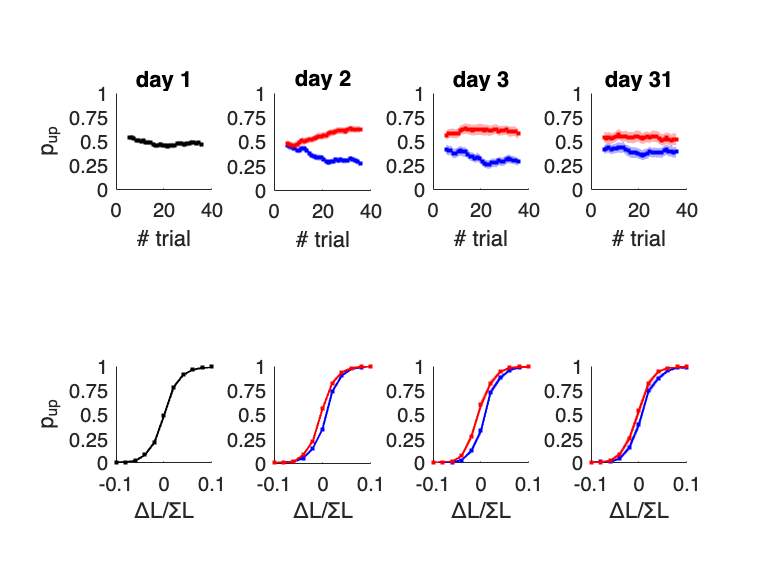

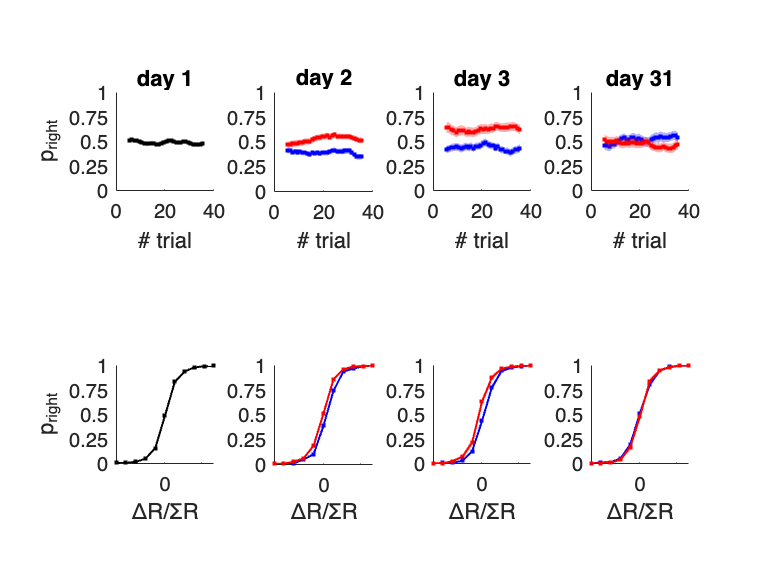

xLab.Vertical = '\DeltaL/\SigmaL';
xLab.Horizontal = '\DeltaR/\SigmaR';
winSize = 10;
thisMans = [-1,1];
manipNames = {'decrease','increase'};
colMans = [0,0,1; 1,0,0];
firstDay = 1;
dataName = 'feedback';
timeNames = dataTimeGroupNames.(dataName);
relField = 'oldResponse';

for task = 1:length(taskNames)
    taskName = taskNames{task};
    devVect = devs.(dataName).(taskName);

    fig = figure;
    if task==1
        figName = 'Figure4';
    elseif task==2
        figName = 'FigureS7';
    end

    cell0Group1 = cell(length(timeNames)*length(manipNames),1);
    cellpGroup1 = cell(length(timeNames)*length(manipNames),11);
    for mm = 1:length(manipNames)
        cell0Group2.(manipNames{mm}) = cell(length(timeNames),1);
        cellpGroup2.(manipNames{mm}) = cell(length(timeNames),11);
        for tii = 1:length(timeNames)
            cell0Group3.(manipNames{mm}).(timeNames{tii}) = cell(1,1);
            cellpGroup3.(manipNames{mm}).(timeNames{tii}) = cell(1,11);
        end
    end

    % load relevant data:
    for ti = 1:length(timeNames)
        timeName = timeNames{ti}; 
        for m = 1:length(thisMans)
            thisMan = thisMans(m);
            manipName = manipNames{m};
            man =  behav.(dataName).(taskName).(timeName).manip;
            cell0Group1{m+length(thisMans)*(ti-1)} = ...
                behav.(dataName).(taskName).(timeName...
                ).sess1.dev0.(relField).mat( man == thisMan, : );
            cell0Group2.(manipName){ti,1} = ...
                behav.(dataName).(taskName).(timeName...
                ).sess2.dev0.(relField).mat( man == thisMan, : );
            cell0Group3.(timeName).(manipName){1,1} = ...
                behav.(dataName).(taskName).(timeName...
                ).sess3.dev0.(relField).mat( man == thisMan, : );

            for d = 1:length(devVect)
                thisDev = devVect(d);
                if thisDev >=0
                    devName = ['dev' num2str(thisDev)];
                else
                    devName = ['dev' 'm' num2str(abs(thisDev))];
                end
                cellpGroup1{m+length(thisMans)*(ti-1),d} = ...
                    behav.(dataName).(taskName).(timeName...
                    ).sess1.(devName).(relField).mean( man == thisMan );
                cellpGroup2.(manipName){ti,d} = ...
                    behav.(dataName).(taskName).(timeName...
                    ).sess2.(devName).(relField).mean( man == thisMan );
                cellpGroup3.(timeName).(manipName){1,d} = ...
                    behav.(dataName).(taskName).(timeName...
                    ).sess3.(devName).(relField).mean( man == thisMan );
            end
        end
    end

    % plot running window:

    % 1st session (all manips, all time groups):
    subplot(2,4,1);
    runningWindow( cell2mat(cell0Group1), winSize, 'on', [0,0,0] );
    xlabel('# trial'); ylabel(yLab.(taskName));
    title(['day ' num2str( round(firstDay) )]);
    for mmm = 1:length(manipNames)
        % 2nd session (separate manipulations, unite time conditions):
        subplot(2,4,2);
        runningWindow( cell2mat(cell0Group2.(manipNames{mmm})), ...
            winSize, 'on', colMans(mmm,:) ); hold on;
        for tiii = 1:length(timeNames)
            % 3rd session (separate manipulations and time conditions):
            subplot(2,4,2+tiii);
            runningWindow( cell2mat(cell0Group3.(timeNames{tiii}...
                ).(manipNames{mmm})), winSize, 'on', colMans(mmm,:) ); 
            hold on;
        end
    end
    subplot(2,4,2);
    title(['day ' num2str( round(firstDay+.5*( ...
        mDelDay31_day - mDelDay32_day + ...
        mDelDay31_month - mDelDay32_month)) )]);
    subplot(2,4,3);
    title(['day ' num2str( round(firstDay + mDelDay31_day) )]);
    subplot(2,4,4); 
    title(['day ' num2str( round(firstDay + mDelDay31_month) )]);

    % plot psychometric curve:
    
    % 1st session (all manips, all time groups):
    subplot(2,4,5);
    psychometric( cell2mat(cellpGroup1), devVect / toNormDev.(taskName), ...
        'on', [0,0,0] );
    ylabel(yLab.(taskName));
    for mmm = 1:length(manipNames)
        % 2nd session (separate manipulations, unite time conditions):
        subplot(2,4,6);
        psychometric( cell2mat(cellpGroup2.(manipNames{mmm})), ...
            devVect / toNormDev.(taskName), 'on', colMans(mmm,:) ); hold on;
        for tiii = 1:length(timeNames)
            % 3rd session (separate manipulations and time conditions):
            subplot(2,4,6+tiii);
            psychometric( cell2mat(cellpGroup3.(timeNames{tiii}...
                ).(manipNames{mmm})), devVect / toNormDev.(taskName), ...
                'on', colMans(mmm,:) ); hold on;
        end
    end
    
    for i = 1:4
        subplot(2,4,i);
        ylim([0,1]); yticks(0:.25:1); xlabel('# trial'); axis square;
        subplot(2,4,4+i);
        ylim([0,1]); yticks(0:.25:1); xlabel(xLab.(taskName)); axis square;
    end
    savefig(fig, ['figures/' figName '.fig']);
    
end

### Fig. 4 - feedback - tests:

#### **Tests for differences between means in the first session:**

dayUp = behav.feedback.Vertical.day.sess1.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.day.manip == 1 );
dayUpName = cell( size(dayUp) );
dayUpName(:) = {'day Up'};
dayDown = behav.feedback.Vertical.day.sess1.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.day.manip == -1 );
dayDownName = cell( size(dayDown) );
dayDownName(:) = {'day Down'};
monthUp = behav.feedback.Vertical.month.sess1.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.month.manip == 1 );
monthUpName = cell( size(monthUp) );
monthUpName(:) = {'month Up'};
monthDown = behav.feedback.Vertical.month.sess1.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.month.manip == -1 );
monthDownName = cell( size(monthDown) );
monthDownName(:) = {'month Down'};
allFeed1 = [dayUp; dayDown; monthUp; monthDown];
allFeed1Name = [dayUpName; dayDownName; monthUpName; monthDownName];
disp('differences between means in the first session:')

differences between means in the first session:


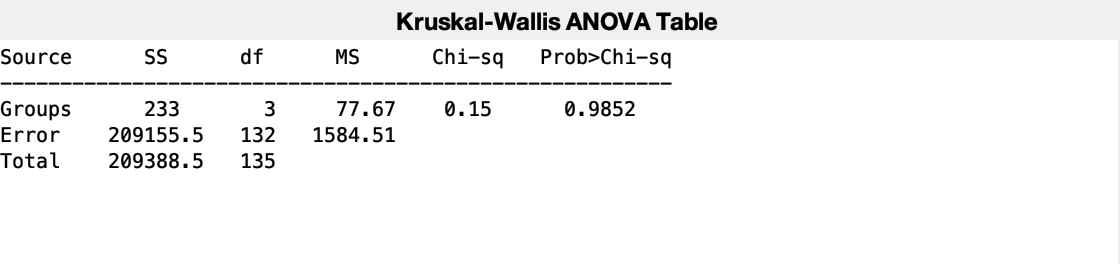

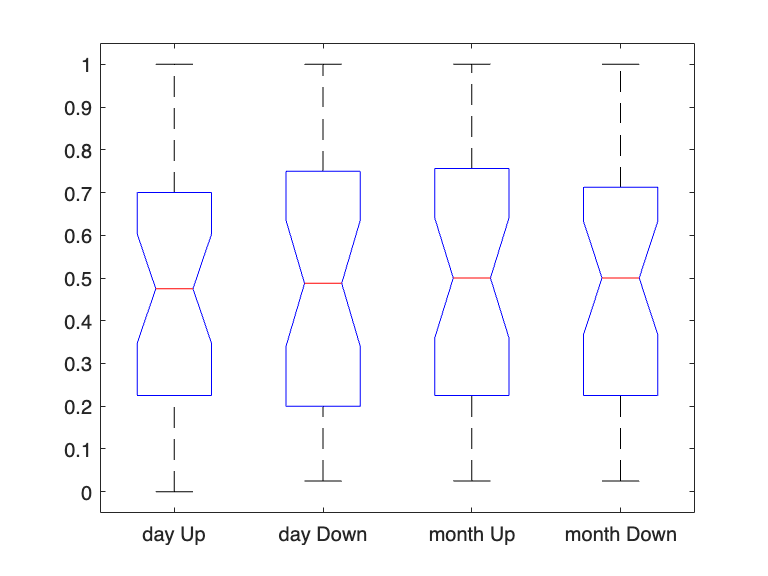

p = 0.9852

stats = struct with fields:
       gnames: {4×1 cell}
            n: [34 34 35 33]
       source: 'kruskalwallis'
    meanranks: [66.6912 67.8382 69.9429 69.5152]
         sumt: 2658


figure;
[p,~,stats] = kruskalwallis( allFeed1, allFeed1Name )

#### **Compare each group individually to 0.5:**

disp('signrank test for ICB-0.5 in delay X feedback groups:')

signrank test for ICB-0.5 in delay X feedback groups:


p = signrank( dayUp-.5 )

p = 0.5980

p = signrank( dayDown-.5 )

p = 0.7613

p = signrank( monthUp-.5 )

p = 0.9255

p = signrank( monthDown-.5 )

p = 0.9702

#### **Wilcoxon rank sum test for the difference in second session ICB medians between-feedback groups (two-sided):**

pDay_manUp = behav.feedback.Vertical.day.sess2.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.day.manip == 1 );
pDay_manDown = behav.feedback.Vertical.day.sess2.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.day.manip == -1 );
pMonth_manUp = behav.feedback.Vertical.month.sess2.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.month.manip == 1 );
pMonth_manDown = behav.feedback.Vertical.month.sess2.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.month.manip == -1 );
pManUp = [pDay_manUp; pMonth_manUp];
pManDown = [pDay_manDown; pMonth_manDown];
disp('ranksum test upVsDown p0sess2:')

ranksum test upVsDown p0sess2:


[p,~,stats] = ranksum(pManUp,pManDown)

p = 2.5020e-06

stats = struct with fields:
       zval: 4.7080
    ranksum: 5808


#### **Wilcoxon rank sum test for the difference in second session MOVING ICB MEDIANS between-feedback groups (one-sided):**

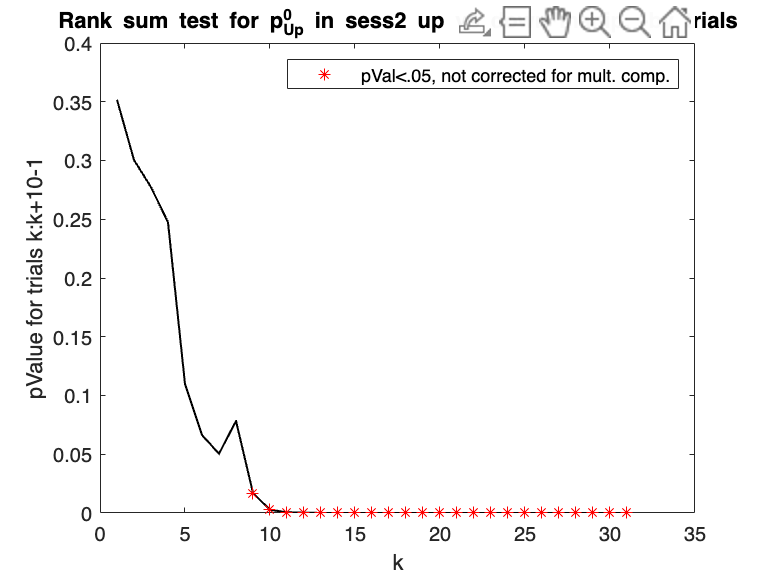

pVal = nan(31,1);
for r = 1:31
    pDay_manUp = mean( ...
        behav.feedback.Vertical.day.sess2.dev0.oldResponse.mat( ...
        behav.feedback.Vertical.day.manip == 1, r:r+10-1 ), 2 );
    pDay_manDown = mean( ...
        behav.feedback.Vertical.day.sess2.dev0.oldResponse.mat( ...
        behav.feedback.Vertical.day.manip == -1, r:r+10-1 ), 2 );
    pMonth_manUp = mean( ...
        behav.feedback.Vertical.month.sess2.dev0.oldResponse.mat( ...
        behav.feedback.Vertical.month.manip == 1, r:r+10-1 ), 2 );
    pMonth_manDown = mean( ...
        behav.feedback.Vertical.month.sess2.dev0.oldResponse.mat( ...
        behav.feedback.Vertical.month.manip == -1, r:r+10-1 ), 2 );
    pManUp = [pDay_manUp; pMonth_manUp];
    pManDown = [pDay_manDown; pMonth_manDown];
    pVal(r) = ranksum(pManUp,pManDown,'tail','right');
end
figure;
iComp = (1:31)';
plot( iComp, pVal, 'k', 'lineWidth', 1 ); hold on;
sigComps = plot( iComp(pVal<.05), pVal(pVal<.05), 'r*' ); 
hold on;
xlabel('k');
ylabel('pValue for trials k:k+10-1');
title('Rank sum test for p_{Up}^0 in sess2 up vs down manip. -by trials')
legend(sigComps,'pVal<.05, not corrected for mult. comp.')

## Fig. 5 - feedback - Decay of the feedback effect

### Fig. 5A (&S8A) - feedback - ICB in second (2nd half) vs last session by delay group:

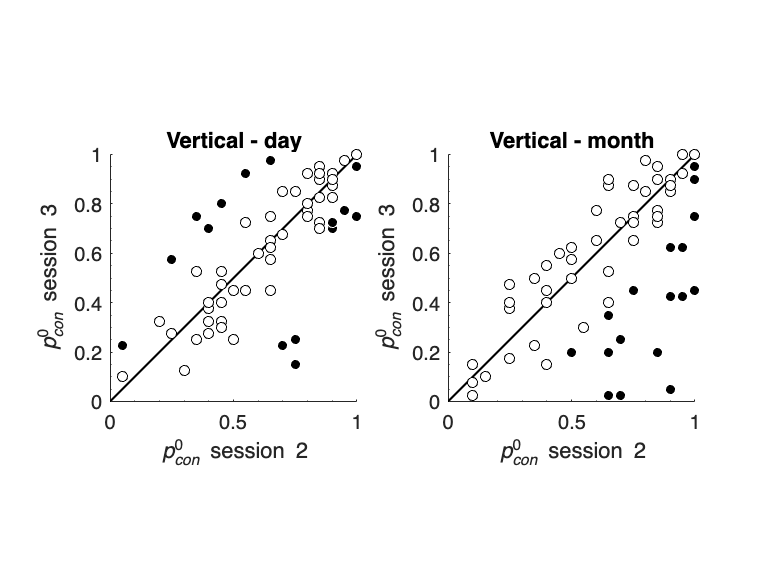

Vertical - day: nSigIncrease = 7


Vertical - day: max(p.value| sig. increase) = 0.025347


Vertical - day: nSigDecrease = 10


Vertical - day: max(p.value| sig. decrease) = 0.033169


Vertical - month: nSigIncrease = 0


Vertical - month: max(p.value| sig. increase) = 


Vertical - month: nSigDecrease = 20


Vertical - month: max(p.value| sig. decrease) = 0.02846


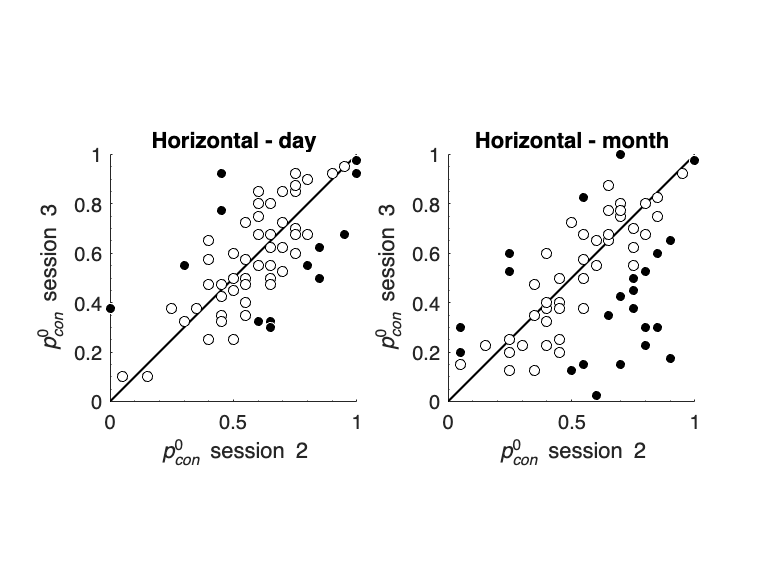

Horizontal - day: nSigIncrease = 4


Horizontal - day: max(p.value| sig. increase) = 0.046366


Horizontal - day: nSigDecrease = 9


Horizontal - day: max(p.value| sig. decrease) = 0.040391


Horizontal - month: nSigIncrease = 7


Horizontal - month: max(p.value| sig. increase) = 0.043546


Horizontal - month: nSigDecrease = 17


Horizontal - month: max(p.value| sig. decrease) = 0.035015


dataName = 'feedback';
timeNames = dataTimeGroupNames.(dataName);
for task = 1:length(taskNames)
    taskName = taskNames{task};
    fig = figure;
    if task==1
        figName = 'Figure5A';
    elseif task==2
        figName = 'FigureS8A';
    end
    for ti = 1:length(timeNames)
        timeName = timeNames{ti};
        subplot(1,2,ti);
        pSess3 = behav.feedback.(taskName).(timeName...
            ).sess3.dev0.responseCongruent.mean;
        pSess2LastHalf = mean( ...
            behav.feedback.(taskName).(timeName...
            ).sess2.dev0.responseCongruent.mat(:,21:40), 2 );
        % Comparing two independent proportions (two-sided, not corrected 
        % for mult. comp):
        pBoth = ( (20*pSess2LastHalf) + (40*pSess2LastHalf) ) / ...
            ( 20 + 40 );
        zScore = (pSess2LastHalf - pSess3) ./ ...
            sqrt( pBoth .* (1-pBoth) * ( (1/20) +(1/40) ) );
        pVal = 2*(1-normcdf(abs(zScore)));
        % Store num sig. in each direction
        pCon32NumSigChange.(taskName).(timeName).increase = ...
            sum( (pVal<=0.05) & (pSess3 > pSess2LastHalf) );
        pCon32NumSigChange.(taskName).(timeName).decrease = ...
            sum( (pVal<=0.05) & (pSess3 < pSess2LastHalf) );
        % Store max pVal in each direction:
        pCon32MaxPValSigChange.(taskName).(timeName).increase = ...
            max( pVal( (pVal<=0.05) & (pSess3 > pSess2LastHalf) ) );
        pCon32MaxPValSigChange.(taskName).(timeName).decrease = ...
            max( pVal( (pVal<=0.05) & (pSess3 < pSess2LastHalf) ) );
        % Plot:
        plot( [0,1], [0,1], 'k', 'lineWidth', 1 ); hold on;
        plot( pSess2LastHalf(pVal<=0.05), pSess3(pVal<=0.05), ...
            'Marker', 'o', 'MarkerSize', 5, ...
            'MarkerFaceColor', 'k', 'MarkerEdgeColor', [1 1 1], ...
            'lineStyle', 'none'); hold on;
        plot( pSess2LastHalf(pVal>0.05), pSess3(pVal>0.05), ...
            'Marker', 'o', 'MarkerSize', 5, ...
            'MarkerFaceColor', [1 1 1], 'MarkerEdgeColor', [0 0 0], ...
            'lineStyle', 'none'); hold on;
        % Add nan pVal (not sig., both pCon2 and pCon3 = 0 or 1):
        plot( pSess2LastHalf(isnan(pVal)), pSess3(isnan(pVal)), ...
            'Marker', 'o', 'MarkerSize', 5, ...
            'MarkerFaceColor', [1 1 1], 'MarkerEdgeColor', [0 0 0], ...
            'lineStyle', 'none'); hold on;
        xlabel('{\itp}^0_{{\itcon}} session 2');
        ylabel('{\itp}^0_{{\itcon}} session 3')
        box off; axis square; xlim([0,1]); ylim([0,1]);
        ggg = gca; ggg.XMinorTick = 'on'; ggg.YMinorTick = 'on'; 
        title([taskName ' - ' timeName]);
        savefig(fig, ['figures/' figName '.fig']);
    end
    % Print num. sig. pCon increase/decrease in each delay-group and
    % corresp. max(pVal)
    disp([taskName ' - day: nSigIncrease = ' num2str(...
        pCon32NumSigChange.(taskName).day.increase)]);
    disp([taskName ' - day: max(p.value| sig. increase) = ' ...
        num2str(pCon32MaxPValSigChange.(taskName).day.increase)]);
    disp([taskName ' - day: nSigDecrease = ' num2str(...
        pCon32NumSigChange.(taskName).day.decrease)]);
    disp([taskName ' - day: max(p.value| sig. decrease) = ' ...
        num2str(pCon32MaxPValSigChange.(taskName).day.decrease)]);
    disp([taskName ' - month: nSigIncrease = ' num2str(...
        pCon32NumSigChange.(taskName).month.increase)]);
    disp([taskName ' - month: max(p.value| sig. increase) = ' ...
        num2str(pCon32MaxPValSigChange.(taskName).month.increase)]);
    disp([taskName ' - month: nSigDecrease = ' num2str(...
        pCon32NumSigChange.(taskName).month.decrease)]);
    disp([taskName ' - month: max(p.value| sig. decrease) = ' ...
        num2str(pCon32MaxPValSigChange.(taskName).month.decrease)]);

end

### Fig. 5B (&S8B) - feedback - ICB in second vs last session by delay group - discrete violins:

**Plot doscrete violins of mean delta p = p3-p2:**

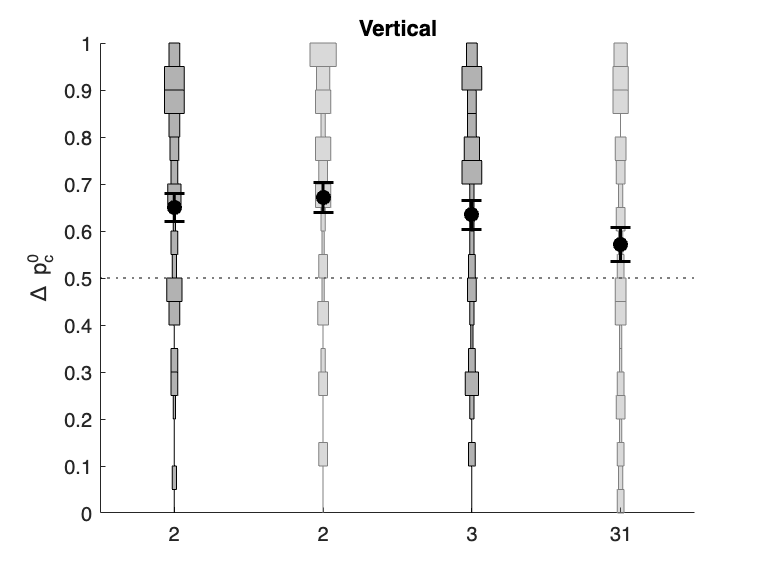

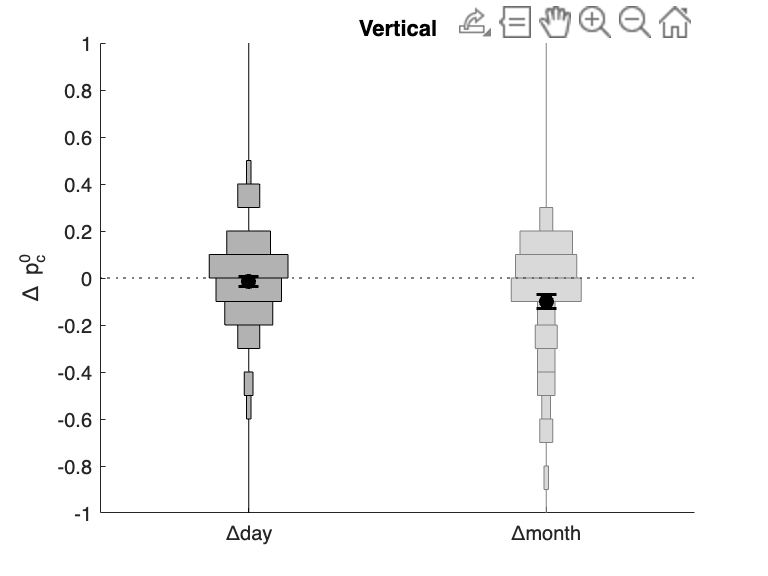

Vertical - day signrank: p=0.4313, zval=0.78697


Vertical - month signrank: p=0.013029, zval=2.483


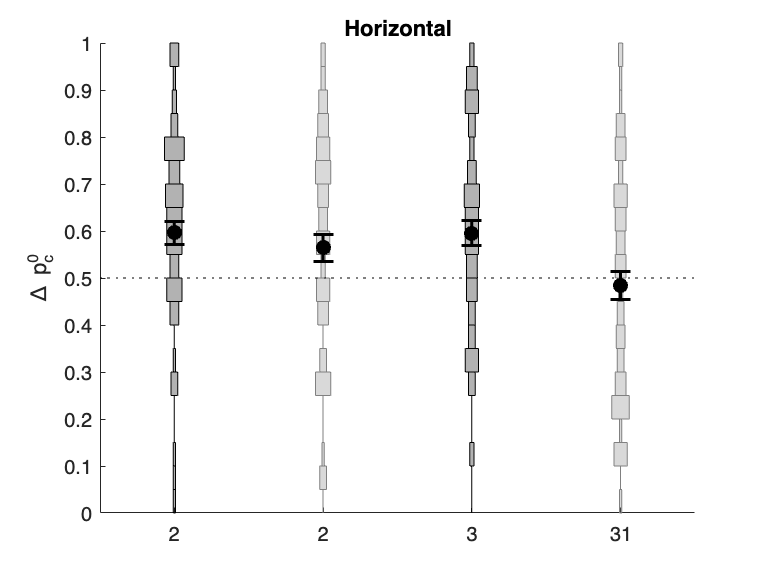

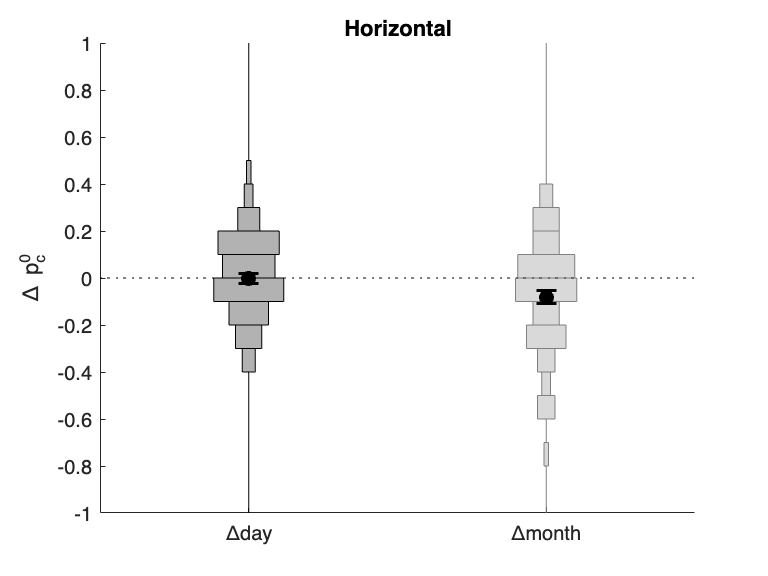

Horizontal - day signrank: p=0.88563, zval=0.14384


Horizontal - month signrank: p=0.020072, zval=2.325


dataName = 'feedback';
timeNames = dataTimeGroupNames.(dataName);
for task = 1:2
    taskName = taskNames{task};
    if task==1
        figName = 'Figure5B';
    elseif task==2
        figName = 'FigureS8B';
    end
    % Prepare data
    pSess3_day = behav.feedback.(taskName).day.sess3.dev0.responseCongruent.mean;
    pSess2LastHalf_day = mean( behav.feedback.(taskName...
        ).day.sess2.dev0.responseCongruent.mat(:,21:40), 2 );
    pSess3_month = behav.feedback.(taskName...
        ).month.sess3.dev0.responseCongruent.mean;
    pSess2LastHalf_month = mean( behav.feedback.(taskName...
        ).month.sess2.dev0.responseCongruent.mat(:,21:40), 2 );
    % Plot violins of second AND last session by delay group:
    plotDiscreteViolin( ...
        {pSess2LastHalf_day, pSess2LastHalf_month, pSess3_day, pSess3_month}, ...
        0:.05:1, ...
        {'2', '2', '3', '31'}, ...
        taskNames(task), ...
        [0 0 0; .5 .5 .5; 0 0 0; .5 .5 .5] );
    savefig(gcf,['figures/' figName '1.fig']);
    % Plot violins of second MINUS last session by delay group:
    deltaP_day = pSess3_day - pSess2LastHalf_day;
    deltaP_month = pSess3_month - pSess2LastHalf_month;
    plotDiscreteViolin( ...
        {deltaP_day, deltaP_month}, ...
        -1:.1:1, ...
        {'\Deltaday', '\Deltamonth'}, ...
        taskNames(task), ...
        [0 0 0; .5 .5 .5; 0 0 0; .5 .5 .5] );
    savefig(gcf,['figures/' figName '2.fig']);
    % Also run ranksum per delay group:
    for ti = 1:length(timeNames)
        timeName = timeNames{ti};
        pSess3 = behav.feedback.(taskName).(timeName...
            ).sess3.dev0.responseCongruent.mean;
        pSess2LastHalf = mean( ...
            behav.feedback.(taskName).(timeName...
            ).sess2.dev0.responseCongruent.mat(:,21:40), 2 );
        [p,h,stats] = signrank(pSess2LastHalf-pSess3);
        pVal_ranksum.(taskName).(timeName) = p;
        zVal_ranksum.(taskName).(timeName) = stats.zval;
    end 
    disp([taskName ' - day signrank: p=' num2str( ...
        pVal_ranksum.(taskName).day ) ', zval=' num2str( ...
        zVal_ranksum.(taskName).day)])
    disp([taskName ' - month signrank: p=' num2str( ...
        pVal_ranksum.(taskName).month ) ', zval=' num2str( ...
        zVal_ranksum.(taskName).month)])
end

**Repeat for Extended data Fig. 3B (&S6B)**

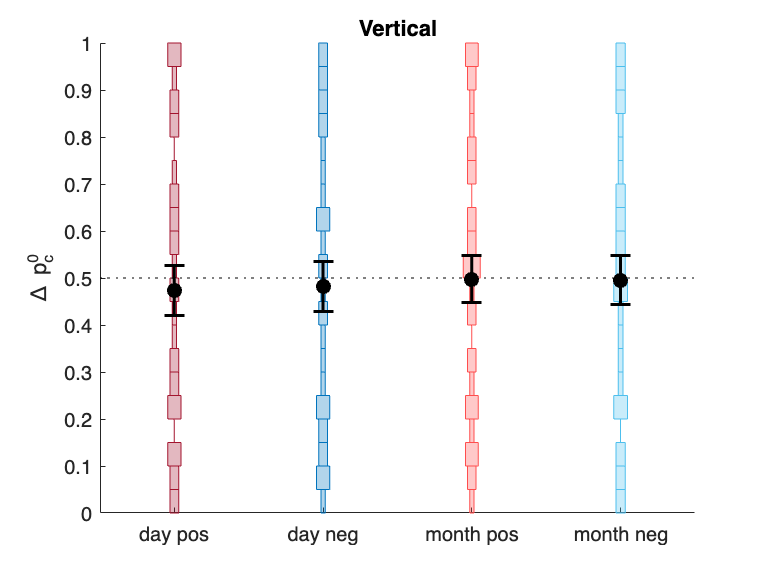

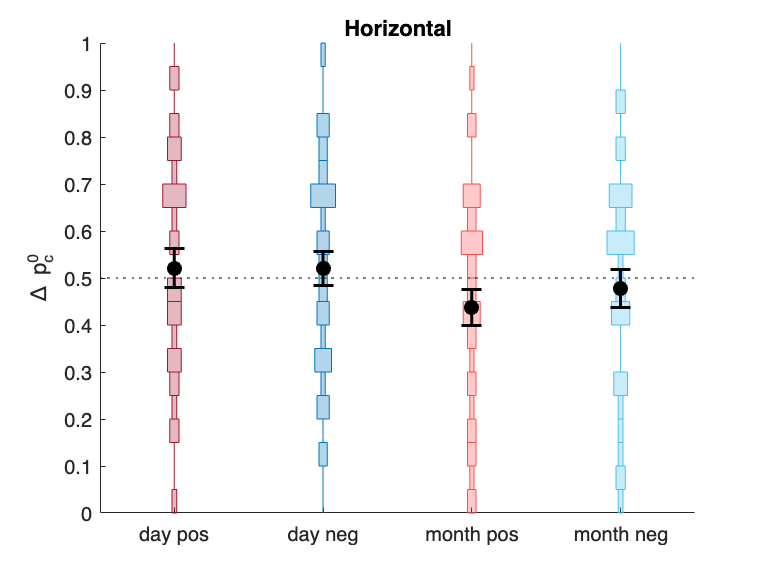

for task = 1:2
    taskName = taskNames{task};
    % Prepare data
    pDay_manPos = ...
        behav.feedback.(taskName).day.sess1.dev0.oldResponse.mean( ...
        behav.feedback.(taskName).day.manip == 1 );
    pDay_manNeg = ...
        behav.feedback.(taskName).day.sess1.dev0.oldResponse.mean( ...
        behav.feedback.(taskName).day.manip == -1 );
    pMonth_manPos = ...
        behav.feedback.(taskName).month.sess1.dev0.oldResponse.mean( ...
        behav.feedback.(taskName).month.manip == 1 );
    pMonth_manNeg = ...
        behav.feedback.(taskName).month.sess1.dev0.oldResponse.mean( ...
        behav.feedback.(taskName).month.manip == -1 );
    % Plot violins by delay * manip group:
    plotDiscreteViolin( ...
        {pDay_manPos, pDay_manNeg, pMonth_manPos, pMonth_manNeg}, ...
        0:.05:1, ...
        {'day pos', 'day neg', 'month pos', 'month neg'}, ...
        taskNames(task), ...
        [.64,.08,.18; 0,.45,.74; 1,.3,.3; .3,.75,.93] );
end

### Fig. 5 - feedback - tests:

#### **Wilcoxon rank sum test for the difference in third session ICB medians between-feedback groups (two-sided) IN EACH DELAY GROUP:**

pDay_manUp = ...
    behav.feedback.Vertical.day.sess3.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.day.manip == 1 );
pDay_manDown = ...
    behav.feedback.Vertical.day.sess3.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.day.manip == -1 );
pMonth_manUp = ...
    behav.feedback.Vertical.month.sess3.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.month.manip == 1 );
pMonth_manDown = ...
    behav.feedback.Vertical.month.sess3.dev0.oldResponse.mean( ...
    behav.feedback.Vertical.month.manip == -1 );
% compare effects in the third session - 1 day:
disp('ranksum test upVsDown p0sess3 day:')

ranksum test upVsDown p0sess3 day:


[p,~,stats] = ranksum(pDay_manUp,pDay_manDown)

p = 6.6073e-05

stats = struct with fields:
       zval: 3.9900
    ranksum: 1.4985e+03


% compare effects in the third session - 1 month:
disp('ranksum test upVsDown p0sess3 month:')

ranksum test upVsDown p0sess3 month:


[p,~,stats] = ranksum(pMonth_manUp,pMonth_manDown)

p = 0.0629

stats = struct with fields:
       zval: 1.8601
    ranksum: 1.3595e+03


#### **Exponential decay, estimated tau and tau bootstrapped 95% upper bound:**

disp('Decay estimates:');

Decay estimates:


for task = 1:numel(taskNames)
    taskName = taskNames{task};
    pSess3_month = behav.feedback.(taskName...
        ).month.sess3.dev0.responseCongruent.mean;
    pSess2LastHalf_month = mean( behav.feedback.(taskName...
        ).month.sess2.dev0.responseCongruent.mat(:,21:40), 2 );
    rFeed.(taskName) = (mean(pSess3_month)-.5) / ...
        (mean(pSess2LastHalf_month)-.5);
    disp([taskName ' (p3-0.5)/(p2-0.5) = ' ...
        num2str(rFeed.(taskName))]);
end

Vertical (p3-0.5)/(p2-0.5) = 0.41416
Horizontal (p3-0.5)/(p2-0.5) = -0.26437



% --> Focus on vertical as horizontal r < 0.
taskName = 'Vertical';
pSess3_month = behav.feedback.(taskName...
    ).month.sess3.dev0.responseCongruent.mean;
pSess2LastHalf_month = mean( behav.feedback.(taskName...
    ).month.sess2.dev0.responseCongruent.mat(:,21:40), 2 );
% Compute tau (in months):
estimated_tau = -1 / log(rFeed.(taskName));
disp([taskName ' estimated tau, assuming:']);

Vertical estimated tau, assuming:


disp('[p(t=1)-0.5] = [p(t=0)-0.5]*exp(-t/tau)');

[p(t=1)-0.5] = [p(t=0)-0.5]*exp(-t/tau)


disp(['--> tau = ' num2str(estimated_tau) ' months']);

--> tau = 1.1344 months


estimated_decayTo1per = -estimated_tau * log(.01);
disp(['--> t|1% = ' num2str(estimated_decayTo1per) ' months']);

--> t|1% = 5.2243 months



% Bootstrap participants for estimated tau 95% CI:
nSims = 1e6;
rFeedVerSim = nan(nSims,1);
nLocs = length(pSess3_month);
posLocs = 1:nLocs;
for s = 1:nSims
    locSim = datasample( posLocs, nLocs );
    sim_pSess3_month = pSess3_month(locSim);
    sim_pSess2LastHalf_month = pSess2LastHalf_month(locSim);
    rFeedVerSim(s) = (mean(sim_pSess3_month)-.5) / ...
        (mean(sim_pSess2LastHalf_month)-.5);
end
sim_r_q95 = quantile(rFeedVerSim,.95);
disp([taskName ' bootstrap (p3-0.5)/(p2-0.5):']);

Vertical bootstrap (p3-0.5)/(p2-0.5):


disp(['r SEM (bootstrap std) = ' num2str(std(rFeedVerSim))]);

r SEM (bootstrap std) = 0.18445


disp(['r 95% upper: ' num2str(sim_r_q95)]);

r 95% upper: 0.67778


disp(['Corresponding tau 95% upper: ' ...
    num2str(-1 / log(sim_r_q95)) ' months']);

Corresponding tau 95% upper: 2.5711 months


## Fig. 6 - feedback - Instability of the feedback effect:

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

#### Compute delay-group between session ICB correlation and 95% CI's:

### Fig. 6A (&S9A) - feedback - ICB in the first vs last session by delay group and biased-feedback:

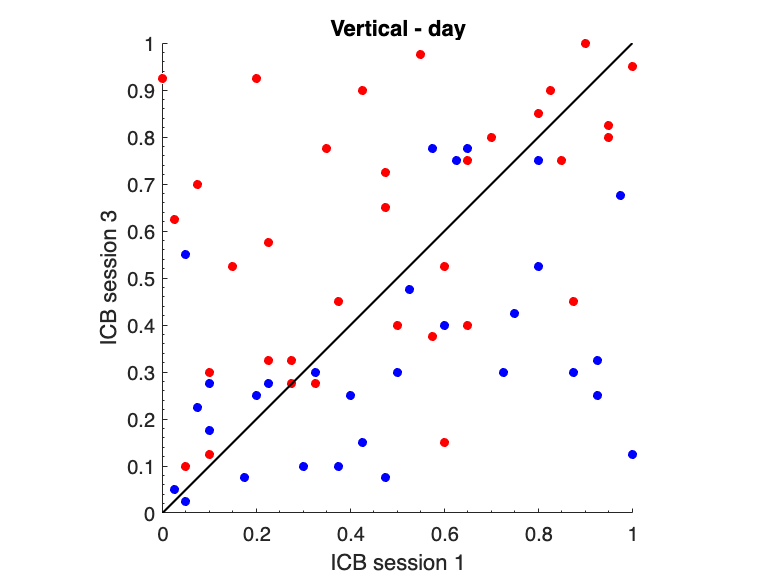

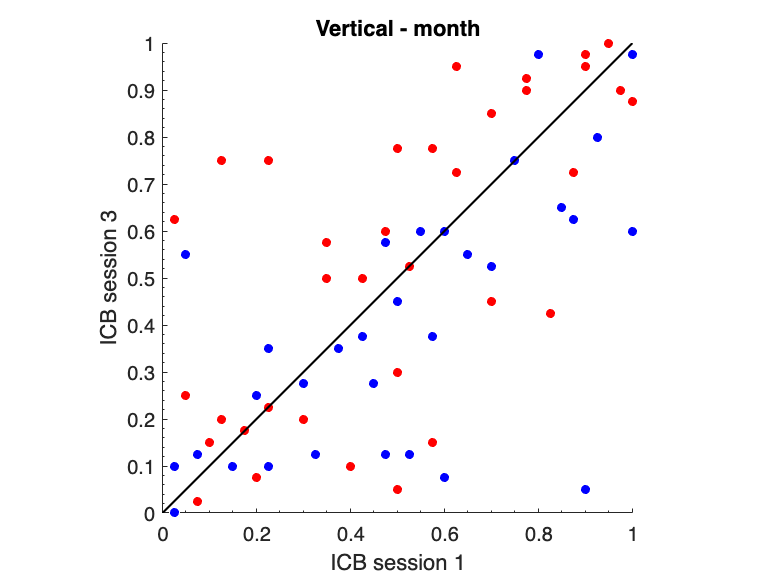

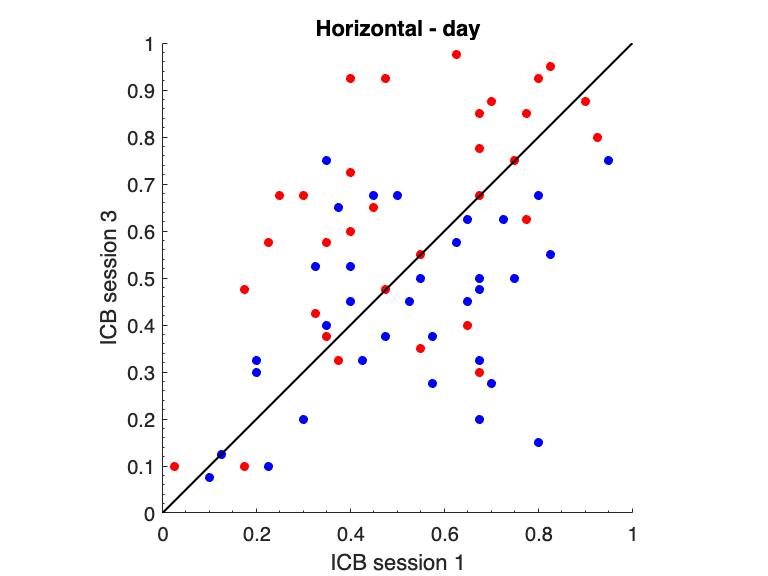

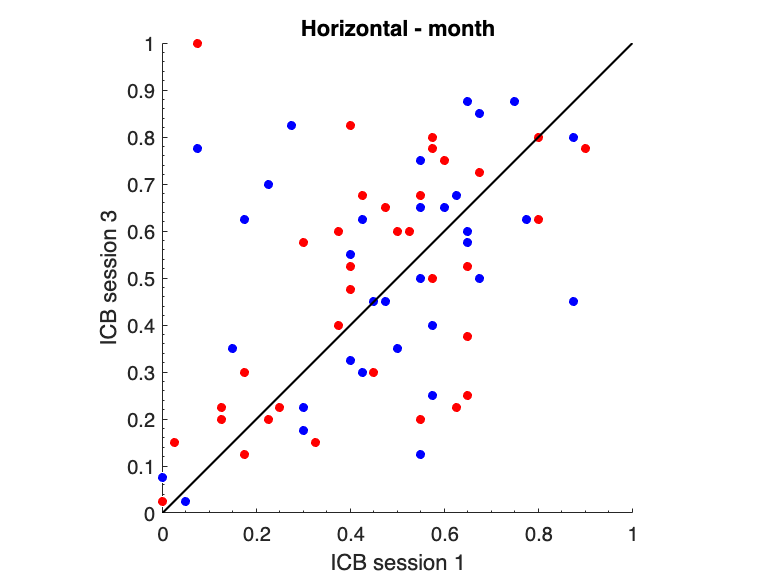

dataName = 'feedback';
timeNames = dataTimeGroupNames.(dataName);
leg = cell(1,4);
for task = 1:length(taskNames)
    taskName = taskNames{task};
    if task==1
        figName = 'Figure6A';
    elseif task==2
        figName = 'FigureS9A';
    end
    for ti = 1:length(timeNames)
        timeName = timeNames{ti};
        fig = figure;
        p1 = behav.(dataName).(taskName).(timeName ...
            ).sess1.dev0.oldResponse.mean;
        p3 = behav.(dataName).(taskName).(timeName ...
            ).sess3.dev0.oldResponse.mean;
        man =  behav.(dataName).(taskName).(timeName).manip;
        clear plt leg;
        for m = 1:2
            thisMan = thisMans(m);
            colMan = colMans(m,:);
            p1m = p1(man == thisMan);
            p3m = p3(man == thisMan);
            plt(1+2*(m-1)) = plot( p1m, p3m, ...
                'Marker', 'o', 'MarkerSize', 5, ...
                'MarkerFaceColor', colMan, 'MarkerEdgeColor', [1 1 1], ...
                'lineStyle', 'none'); hold on;
            plt(2+2*(m-1)) = plot( [0,1], [0,1], 'Color', 'k', ...
                'lineWidth', 1 ); hold on;
        end
        xlabel('ICB session 1');
        ylabel('ICB session 3')
        box off; axis square; xlim([0,1]); ylim([0,1]);
        ggg = gca; ggg.XMinorTick = 'on'; ggg.YMinorTick = 'on'; 
        title([taskName ' - ' timeName]);
        savefig(fig,['figures/' figName '_' num2str(ti) '.fig']);
    end
end

### Fig. 6B (&S9B) - feedback - ICB correlation across sessions:

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

#### Compute delay-group between session ICB correlation and 95% CI's:

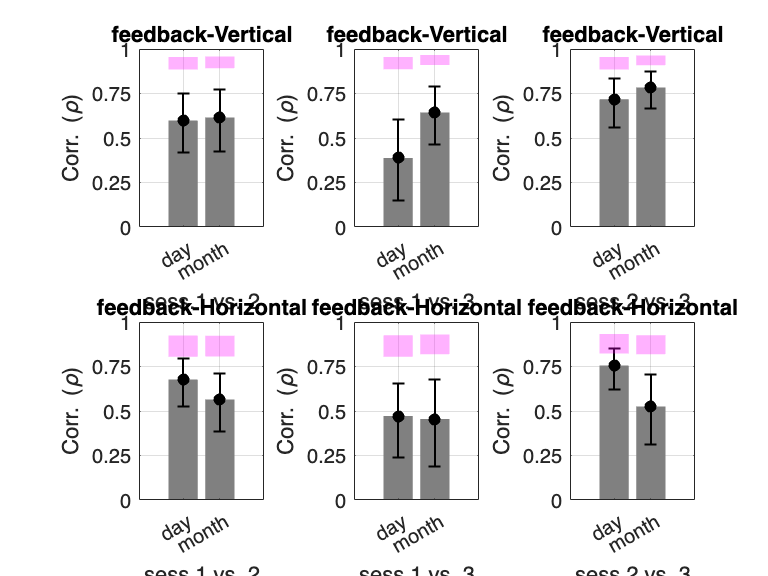

choiceFields.feedback = 'oldResponse';
nLastSess.feedback = 3;
nComps.feedback = 3;
nSims = 1e5;
dataName = 'feedback';

% read mean days between sessions:
deltaTimeTable = readtable('feedback13_deltaTime2ndLast.csv');
addTimeName = '1';
timeNames = dataTimeGroupNames.(dataName);
dayMean.(dataName) = nan(1,length(timeNames));
for ti = 1:length(timeNames)
    timeName = timeNames{ti};
    dayMean.(dataName)(ti) = deltaTimeTable( strcmp( ...
        deltaTimeTable.timeCondition, [addTimeName timeName]), : ).mean;
end

% Compute delay-group between session ICB correlation and 95% CI's:
dat = 2;
dataName = dataNames{dat};
nComp = nComps.(dataName);
timeNames = dataTimeGroupNames.(dataName);
timeNames2 = dataTimeGroupNames2.(dataName);
figBars = figure;
for task = 1:length(taskNames)
    taskName = taskNames{task};
    nSessions = nLastSess.(dataName);
    if task==1
        figName = 'Figure6B';
    elseif task==2
        figName = 'FigureS9B';
    end
    for oth = 1:(nSessions-1)
        for oth2 = oth+1:nSessions
            figure(figBars);
            subplot(2,nComp, oth+oth2 - 2 + (nComp)*(task-1));
            corrTask = nan(1,length(timeNames));
            sigTask = nan(1,length(timeNames));
            corrTask_95sim_sub = nan(2,length(timeNames));
            corrTask_95sim_noStab = nan(2,length(timeNames));
            corrTask_95sim_compStab = nan(2,length(timeNames));
            pVal_corrTask_sim_compStab = nan(1,length(timeNames));
            for ti = 1:length(timeNames)
                timeName = timeNames{ti};
                fieldName = choiceFields.(dataName);
                p1 = behav.(dataName).(taskName).(timeName).(...
                    ['sess' num2str(oth)]).dev0.(fieldName).mean;
                pOther = behav.(dataName).(taskName).(timeName).(...
                    ['sess' num2str(oth2)]).dev0.(fieldName).mean;
                [rho,pVal] = corr(p1,pOther);
                corrTask(ti) = rho;
                sigTask(ti) = pVal;
                simCorr = nan(nSims,1);
                simCorr_noStab = nan(nSims,1);
                simCorr_compStab = nan(nSims,1);
                for s = 1:nSims
                    locSim = datasample( 1:length(p1), length(p1) );
                    locSim2 = datasample( 1:length(p1), length(p1) );
                    % bootstrap corr by subjects:
                    p1Sim = p1(locSim);
                    pOtherSim = pOther(locSim);
                    simCorr(s) = corr(p1Sim,pOtherSim);
                    % bootstrap corr by subjects assuming no stability:
                    p1Sim = p1(locSim);
                    pOtherSim = pOther(locSim2);
                    simCorr_noStab(s) = corr(p1Sim,pOtherSim);
                    % assuming complete stability:
                    % Here, we boostap and also binomrnd the mean p's, to
                    % simulate the corr expected under the assumption that 
                    % the inherent p hadn't changed. Note that this will
                    % only serve as a lower bound for complete stability,
                    % and that this simulation is biased, e.g.,
                    % beacause it has the potential to decrease the 
                    % variance between participants. 
                    pMeanBoot = .5 * (p1(locSim) + pOther(locSim) );
                    p1Sim = (1/nTrialsDevSessImp) * binornd( ...
                        nTrialsDevSessImp, pMeanBoot );
                    pOtherSim = (1/nTrialsDevSessImp) * binornd( ...
                        nTrialsDevSessImp, pMeanBoot );
                    simCorr_compStab(s) = corr(p1Sim,pOtherSim);
                end
                corrTask_95sim_sub(:,ti) = quantile( simCorr, [.025;.975] );
                corrTask_95sim_noStab(:,ti) = quantile( simCorr_noStab, ...
                    [.025;.975] );
                corrTask_95sim_compStab(:,ti) = quantile( ...
                    simCorr_compStab, [.025;.975] );
                pVal_corrTask_sim_compStab(ti) = mean( ...
                    simCorr_compStab < corrTask(ti) );
            end
            
            % plot correlation and bootstrap-based 95% CI's:
            figure(figBars);
            b = bar( 1:length(timeNames), corrTask, 'faceColor', [.5,.5,.5], ...
                'edgeColor', 'none');
            hold on;
            errorbar( 1:length(timeNames), corrTask, ...
                corrTask - corrTask_95sim_sub(1,:), ...
                -corrTask + corrTask_95sim_sub(2,:), 'lineStyle', 'none', ...
                'Color', 'k', 'lineWidth', 1 ); hold on;
            barWidth = b.BarWidth;
            for ttt = 1:length(timeNames)
                patch( [ttt-.5*barWidth, ttt-.5*barWidth, ...
                    ttt+.5*barWidth, ttt+.5*barWidth], ...
                    [corrTask_95sim_compStab(1,ttt), ...
                    corrTask_95sim_compStab(2,ttt), ...
                    corrTask_95sim_compStab(2,ttt), ...
                    corrTask_95sim_compStab(1,ttt)], ...
                    'm', 'EdgeColor', 'none', 'FaceAlpha', .3 ); hold on;
                plot( ttt, corrTask(ttt), 'marker', 'o', ...
                    'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'none' );
                hold on;
            end
            xticks( 1:length(timeNames) ); xticklabels( timeNames2 );
            ylim([0,1]); yticks(0:.25:1); ylabel('Corr. (\rho)');
            grid on;
            xlabel(['sess.' num2str(oth) ' vs. ' num2str(oth2)]);
            title([dataName '-' taskName]);
            savefig(figBars,['figures/' figName '.fig']);
        end
    end
end

### Fig. 6B tests - bootstrap difference in first and last session correlations between delay groups:

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

#### Compute difference in pUp first and last session correlation: month - day

d1 = behav.feedback.Vertical.day.sess1.dev0.oldResponse.mean;
d3 = behav.feedback.Vertical.day.sess3.dev0.oldResponse.mean;
m1 = behav.feedback.Vertical.month.sess1.dev0.oldResponse.mean;
m3 = behav.feedback.Vertical.month.sess3.dev0.oldResponse.mean;
corrMonth = corr( m3, m1 );
corrDay = corr( d3, d1 );
realCorrDiff = corrMonth - corrDay;

#### Exact test - correlation test via Fisher transformation:

TransCorrMonth = .5 * log( (1 + corrMonth) / (1 - corrMonth) );
TransCorrDay = .5 * log( (1 + corrDay) / (1 - corrDay) );
s = sqrt( ( 1 / ( length(d1) - 3 ) ) + ( 1 / ( length(m1) - 3 ) )  );
disp('pValExact: correlation test via Fisher transformation')

pValExact: correlation test via Fisher transformation


pValExact = 1 - normcdf( (TransCorrMonth - TransCorrDay) / s )

pValExact = 0.0216

#### Bootstrap correlation difference:

nSim = 1e6;
simCorrDiff = nan(nSim,1);

% bootsrap corr each individualy -> calc diff:
simCorrDiff_2 = nan(nSim,1); 
simCorr2_day = nan(nSim,1); 
simCorr2_month = nan(nSim,1); 

% bootsrap from both --> calc diff:
simCorrDiff_1 = nan(nSim,1); 
dm1 = [d1;m1];
dm3 = [d3;m3];

sss = RandStream('mlfg6331_64'); 

for s = 1:nSim
    % bootsrap corr each individualy -> calc diff:
    locD = datasample( sss, 1:length(d1), length(d1) );
    locM = datasample( sss, 1:length(m1), length(m1) );
    simCorr2_day(s) = corr( d3(locD), d1(locD) ); 
    simCorr2_month(s) = corr( m3(locM), m1(locM) ); 
    simCorrDiff_2(s) = simCorr2_month(s) - simCorr2_day(s); 
    
    % bootsrap from both --> calc diff:
    locDM = datasample( sss, 1:length(dm1), length(dm1) );
    simCorrDiff_1(s) = corr( dm3(locDM(1:length(d1))), dm1( ...
        locDM(1:length(d1))) ) - ...
        corr( dm3(locDM(1+length(d1):end)), dm1(locDM(1+length(d1):end)) ); 
end

% bootsrap corr each individualy -> calc diff:
mean( simCorrDiff_2 < 0 ) 

ans = 0.0374

% bootsrap from both --> calc diff:
mean( simCorrDiff_1 > realCorrDiff ) 

ans = 0.0412

#### Bootstrap correlation difference:

Simulate the difference in corr(pCon0_sess1,pCon0_sess3) between the two delay groups by bootstrapping participants' identities and corresp. pCongruent either:

(a) separately from each delay group, or

(b) irrespective of the delay group.

pCon3day = behav.feedback.Vertical.day.sess3.dev0.responseCongruent.mean;
pCon1day = behav.feedback.Vertical.day.sess1.dev0.responseCongruent.mean;
pCon3month = ...
    behav.feedback.Vertical.month.sess3.dev0.responseCongruent.mean;
pCon1month = ...
    behav.feedback.Vertical.month.sess1.dev0.responseCongruent.mean;
realCorrDiff = corr(pCon3month,pCon1month) - corr(pCon3day,pCon1day);
pCon1both = [pCon1day; pCon1month];
pCon3both = [pCon3day; pCon3month];
nSims = 1e6; 
simCorrDay = nan(nSims,1);
simCorrMonth = nan(nSims,1);
simCorrDay_rand = nan(nSims,1);
simCorrMonth_rand = nan(nSims,1);
simCorrDay_rand_noRet = nan(nSims,1);
simCorrMonth_rand_noRet = nan(nSims,1);
nDay = length(pCon3day);
nMonth = length(pCon3month);
sss = RandStream('mlfg6331_64'); 
for s = 1:nSims
    % (a) Bootstrap participants corresp. pCon0's separately for each delay 
        % group:
    sLocDay = datasample( sss, 1:nDay, nDay );
    sLocMonth = datasample( sss, 1:nMonth, nMonth );
    simCorrDay(s) = corr( pCon1day(sLocDay), pCon3day(sLocDay) );
    simCorrMonth(s) = corr( pCon1month(sLocDay), pCon3month(sLocDay) );
    % (b1) Bootstrap participants corresp. pCon0's irrespective of delay 
        % group [WITH replacement]:
    sLocBoth = datasample( sss, 1:(nDay+nMonth), nDay+nMonth );
    simCorrDay_rand(s) = corr( pCon1both(sLocBoth(1:nDay)), ...
        pCon3both(sLocBoth(1:nDay)) );
    simCorrMonth_rand(s) = corr( pCon1both(sLocBoth(nDay+1:end)), ...
        pCon3both(sLocBoth(nDay+1:end)) );
    % (b2) Bootstrap participants corresp. pCon0's irrespective of delay 
        % group [WITHOUT replacement]:
    sLocBothNR = datasample( sss, 1:(nDay+nMonth), nDay+nMonth, ...
        'Replace', false );
    simCorrDay_rand_noRet(s) = corr( pCon1both(sLocBothNR(1:nDay)), ...
        pCon3both(sLocBothNR(1:nDay)) );
    simCorrMonth_rand_noRet(s) = corr( ...
        pCon1both(sLocBothNR(nDay+1:end)), ...
        pCon3both(sLocBothNR(nDay+1:end)) );
end
% (a) pValue for the difference in corr(pCon0_sess1,pCon0_sess3) between 
    % delay groups [sampled WITH replacement, from each delay group]:
disp('pValue bootstrap deltaCorr pCon0Sess1vs3 sampleFromDelayGroups:')

pValue bootstrap deltaCorr pCon0Sess1vs3 sampleFromDelayGroups:


mean( simCorrDay > simCorrMonth ) 

ans = 0.0455

% (b1) pValue for the difference in corr(pCon0_sess1,pCon0_sess3) between 
    % delay groups [sampled WITH replacement, irrespective of delay group]:
simCorrDiff = simCorrMonth_rand - simCorrDay_rand;
disp('pValue bootstrap_deltaCorr pCon0Sess1vs3 sampleAllParticipants replaceTrue:')

pValue bootstrap_deltaCorr pCon0Sess1vs3 sampleAllParticipants replaceTrue:


mean( simCorrDiff >= realCorrDiff )

ans = 0.0549

% (b2) pValue for the difference in corr(pCon0_sess1,pCon0_sess3) between 
    % delay groups [sampled WITHOUT replacement, irrespective of delay 
    % group]:
simCorrDiff = simCorrMonth_rand_noRet - simCorrDay_rand_noRet;
disp('pValue bootstrap_deltaCorr pCon0Sess1vs3 sampleAllParticipants replaceFalse:')

pValue bootstrap_deltaCorr pCon0Sess1vs3 sampleAllParticipants replaceFalse:


mean( simCorrDiff >= realCorrDiff )

ans = 0.0560

## Fig. S3 & S6 - feedback - ICB in the first session:

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

### Fig. S3A & S6A - feedback - ICB distribution in the first session:

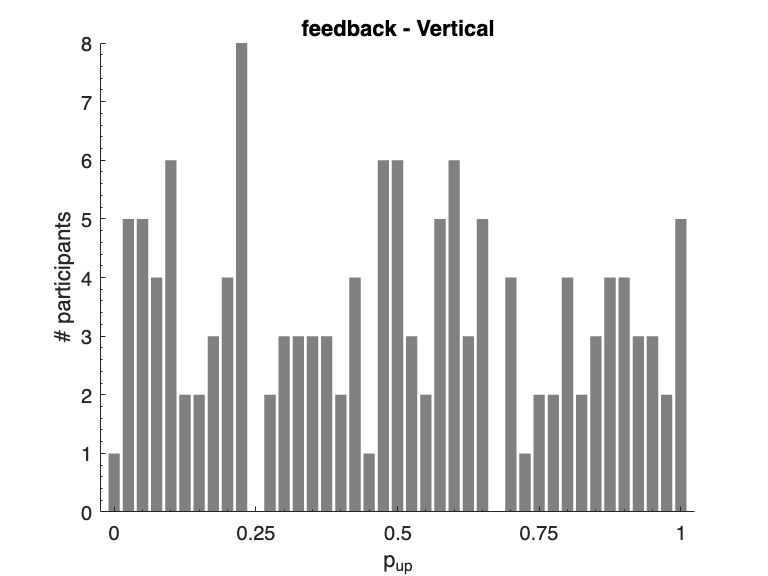

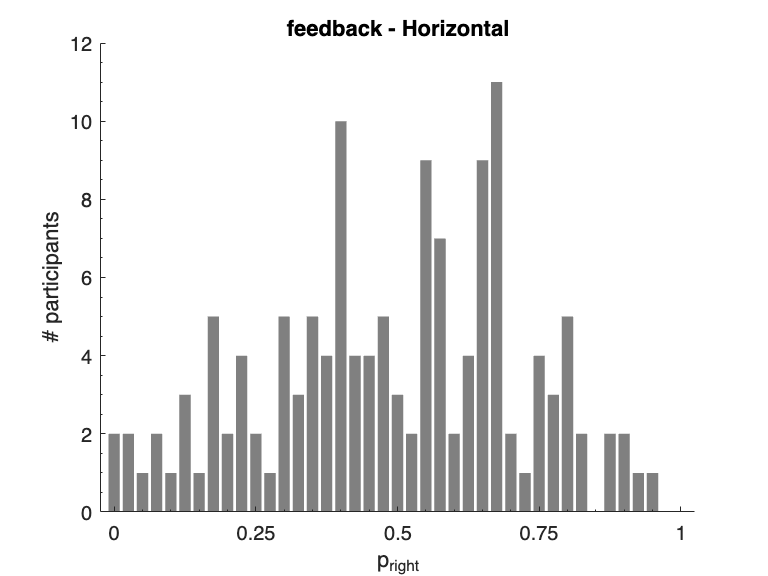

dataName = 'feedback';
timeNames = dataTimeGroupNames.(dataName);
yLab.Vertical = 'p_{up}';
yLab.Horizontal = 'p_{right}';
for task = 1:length(taskNames)
    taskName = taskNames{task};
    if task==1
        figName = 'FigureS3A';
    elseif task==2
        figName = 'FigureS6A';
    end
    edges = linspace(0,1,42);
    pUp0FeedSess1 = [];
    for ti = 1:length(timeNames)
        timeName = timeNames{ti};
        pUp0FeedSess1 = [pUp0FeedSess1; ...
            behav.(dataName).(taskName).(timeName ...
            ).sess1.dev0.oldResponse.mean];
    end
    ICB_BL_pdf = histcounts( pUp0FeedSess1, 'binEdges', edges );
    fig = figure;
    bar( 0:(1/40):1, ICB_BL_pdf, 'FaceColor', [.5 .5 .5], 'edgeColor', ...
        'none' ); 
    xlim([-0.025,1.025]); box off; 
    xlabel(yLab.(taskName)); ylabel('# participants');
    ggg = gca; ggg.XMinorTick = 'on'; ggg.YMinorTick = 'on';
    xticks(0:.25:1); hold on;
    title([dataName ' - ' taskName]);
    savefig(fig,['figures/' figName '.fig']);
end

### Fig. S3B & S6B - feedback - average ICB by feedback X delay, by sess:

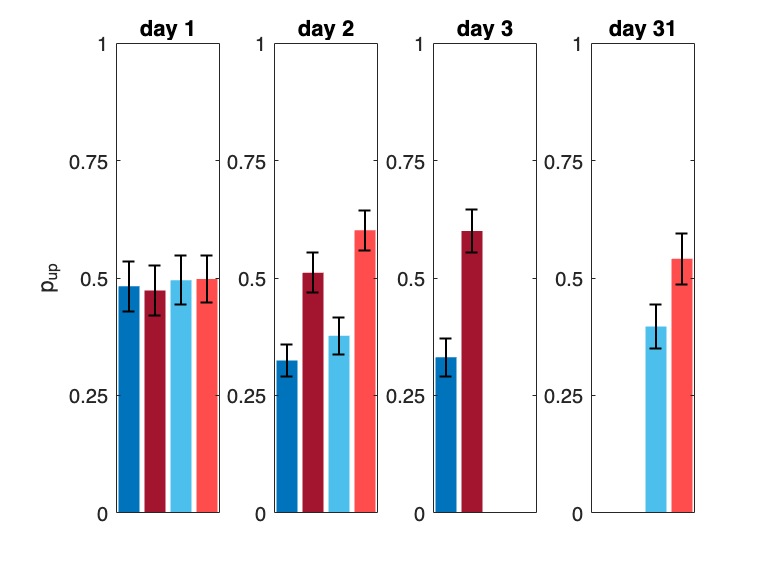

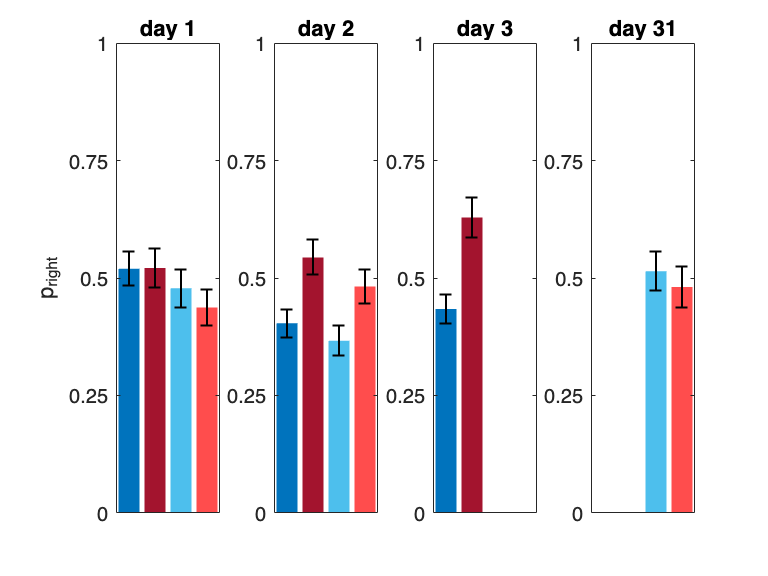

yLab.Vertical = 'p_{up}';
yLab.Horizontal = 'p_{right}';
thisMans = [-1,1];
manipNames = {'decrease','increase'};
clear cols;
cols.day.increase = [.64,.08,.18];
cols.month.increase = [1,.3,.3];
cols.day.decrease = [0,.45,.74];
cols.month.decrease = [.3,.75,.93];

firstDay = 1;
delDay31Table = readtable('feedback13_deltaTime1stLast.csv');
delDay32Table = readtable('feedback13_deltaTime2ndLast.csv');
mDelDay31_day = delDay31Table.mean( strcmp(delDay31Table.timeCondition, ...
    '1day') );
mDelDay32_day = delDay32Table.mean( strcmp(delDay32Table.timeCondition, ...
    '1day') );
mDelDay31_month = delDay31Table.mean( ...
    strcmp(delDay31Table.timeCondition, '1month') );
mDelDay32_month = delDay32Table.mean( ...
    strcmp(delDay32Table.timeCondition, '1month') );

nSessions = 3;

dataName = 'feedback';
timeNames = dataTimeGroupNames.(dataName);
relField = 'oldResponse';

for task = 1:length(taskNames)
    taskName = taskNames{task};
    fig = figure;
    if task==1
        figName = 'FigureS3B';
    elseif task==2
        figName = 'FigureS6B';
    end
    pMean = nan(1,4);
    pSem = nan(1,4);
    colMat = nan(4,3);
    for sess = 1:nSessions
        for ti = 1:length(timeNames)
            timeName = timeNames{ti};
            man = behav.(dataName).(taskName).(timeName).manip;
            for m = 1:length(thisMans)
                thisMan = thisMans(m);
                manipName = manipNames{m};
                pData = behav.(dataName).(taskName).(timeName).(['sess' ...
                    num2str(sess)]).dev0.(relField).mean( ...
                    man == thisMan, : );
                pMean(m+length(thisMans)*(ti-1)) = mean(pData,'omitnan');
                pSem(m+length(thisMans)*(ti-1)) = std(pData,'omitnan') ...
                    / sqrt( sum(~isnan(pData)) );
                colMat(m+length(thisMans)*(ti-1),:) = cols.(timeName).(...
                    manipName);
            end
        end
        if sess ~= 3
            subplot(1,4,sess);
            b = bar( 1:4, pMean );
            b.FaceColor = 'flat';
            b.EdgeColor = 'none';
            b.CData = colMat;
            hold on;
            errorbar( 1:4, pMean, pSem, 'Color', 'k', 'lineWidth', ...
                1, 'lineStyle', 'none' );
            if sess == 1
                ylabel(yLab.(taskName));
            end
        elseif sess == 3
            for tii = 1:2
                subplot(1,4,sess+tii-1);
                locs = (1:2)+2*(tii-1);
                b = bar( locs, pMean(locs) );
                b.FaceColor = 'flat';
                b.EdgeColor = 'none';
                b.CData = colMat(locs,:);
                hold on;
                errorbar( locs, pMean(locs), pSem(locs), 'Color', ...
                    'k', 'lineWidth', 1, 'lineStyle', 'none' ); 
            end
        end
    end
    subplot(1,4,1); 
    title(['day ' num2str( round(firstDay) )]);
    subplot(1,4,2);
    title(['day ' num2str( round(firstDay+.5*( ...
        mDelDay31_day - mDelDay32_day + ...
        mDelDay31_month - mDelDay32_month)) )]);
    subplot(1,4,3);
    title(['day ' num2str( round(firstDay + mDelDay31_day) )]);
    subplot(1,4,4); 
    title(['day ' num2str( round(firstDay + mDelDay31_month) )]);
    for tiii = 1:4
        subplot(1,4,tiii); ylim([0,1]); xlim([.5,4.5]); xticks({});
        yticks(0:.25:1);
    end
    savefig(fig,['figures/' figName '.fig']);
end

### Fig. S3 & S6  - feedback - tests

#### Load processed data and definitions:

%load('behavioralDefs.mat');
%load('behavioralData.mat');

Compare ICB standard deviation in first session of feedback vs stability experiments:

relFields1.stability = 'response';
relFields1.feedback = 'oldResponse';
nSim = 1e6;
for task = 1:length(taskNames)
    taskName = taskNames{task};
    for dat = 1:length(dataNames)
        dataName = dataNames{dat};
        field = relFields1.(dataName);
        timeNames = dataTimeGroupNames.(dataName);
        pChoiceSess1Temp = [];
        for ti = 1:length(timeNames)
            timeName = timeNames{ti};
            pChoiceSess1Temp = [pChoiceSess1Temp; ...
                behav.(dataName).(taskName).(timeName).sess1.dev0.( ...
                field).mean];
        end
        pChoiceSess1.(dataName) = pChoiceSess1Temp;
    end
    % compute real diff in std:
    pStdRealDiff = std( pChoiceSess1.stability ) - std( ...
        pChoiceSess1.feedback );
    pChoiceSess1All = [pChoiceSess1.stability; pChoiceSess1.feedback];
    nStability = length( pChoiceSess1.stability );
    nFeedback = length( pChoiceSess1.feedback );
    % simulate p_std_sess1 for each dataset (stability, feedback):
    pStdSimDiff = nan(nSim,1);
    for s = 1:nSim
        stdStimStability = std( datasample( pChoiceSess1All, ...
            nStability ) );
        stdStimFeedback = std( datasample( pChoiceSess1All, nFeedback ) );
        pStdSimDiff(s) = stdStimStability - stdStimFeedback;
    end
    pVal_pStdStabilityFeedback.(taskName) = ...
        mean( pStdSimDiff >= abs(pStdRealDiff) ) + ...
        mean( pStdSimDiff <= -abs(pStdRealDiff) );
end
pVal_pStdStabilityFeedback

pVal_pStdStabilityFeedback = struct with fields:
      Vertical: 0.8329
    Horizontal: 0.5462


## FUNCTIONS

This code uses 3 custom functions:

(1) runningWindow - see below

(2) psychometric - see below

(3) plotDiscreteViolin - see below

(3) myBinomTest - external. Reference:  Matthew Nelson (2015). [https://www.mathworks.com/matlabcentral/fileexchange/24813-mybinomtest-s-n-p-sided](https://www.mathworks.com/matlabcentral/fileexchange/24813-mybinomtest-s-n-p-sided) MATLAB Central File Exchange. Retrieved February 9, 2016.

### psychometric

function [meanY,semY] = psychometric( data, xDeltaVector, flag, colVect )

% Creates a psychometric curve with mean+-SEM of the input matrix and plot 
% the result by default. Element i,j is the mean of subject i in trial type
% j.
% NaN values are omitted.

% INPUT 1: data is N x M matrix, corresponding to data of N subjects, 
% with M trial difficulty levels. 
% INPUT 2: xDeltaVector is the difficulty level vector.
% INPUT 3 (optional): flag. 'on' (default) plots a corresponding figure. 
% 'off' will not output a plot.
% INPUT 4 (optional): colVect. 1x3 color vect. The default is black.

% OUTPUT 1: meanY is the mean over subjects, for each difficulty.
% OUTPUT 2: semY is the standard error of the mean.

% compute the running window: 
meanY = mean(data, 'omitnan');
semY = std(data, 'omitnan') ./ sqrt( sum(~isnan(data)) );

% plot the results:
if nargin == 2 || (nargin >= 3 && strcmp(flag,'on'))
    if nargin == 4
        col = colVect;
    else
        col = [0,0,0];
    end
    patch( [xDeltaVector, flip(xDeltaVector)], ...
        [meanY + semY, flip(meanY - semY)], ...
        col, 'EdgeColor', 'none', 'FaceAlpha', .3 ); 
    hold on;
    plot( xDeltaVector, meanY, 'Color', col, 'lineWidth', 1, 'Marker', '.' ); 
    hold on;
end

end

### runningWindow

function [meanInWin,semInWin,t] = runningWindow( data, winSize, flag, ...
    colVect )

% Creates a running window of mean+-SEM of the input matrix and plot the 
% result by default, for consecutive winSize trials (e.g., 1:winSize-1, 
% 2:winSize, ... M-winSize+1:M).  
% NaN values are omitted.

% INPUT 1: data is N x M matrix, corresponding to data of N subjects, 
% in M trials. 
% INPUT 2: winSize is the window size.
% INPUT 3 (optional): flag. 'on' (default) plots a corresponding figure. 
% 'off' will not output a plot.
% INPUT 4 (optional): colVect. 1x3 color vect. The default is black.

% OUTPUT 1: meanInWin is the mean in the window.
% OUTPUT 2: semInWin is the standard error of the mean in the window.
% OUTPUT 3: t is the average location of the window. Namely, the sum of the 
% number of first plus last trials in the window, divided by 2. 

% compute the running window: 
nTrials = size(data,2);
meanInWin = nan(1,nTrials+1-winSize);
semInWin = nan(1,nTrials+1-winSize);
t = nan(1,nTrials+1-winSize);
for winStLoc = 1:(nTrials+1-winSize)
    winLocs = winStLoc:(winStLoc+winSize-1);
    winChoices = data(:,winLocs);
    p = mean( winChoices, 2, 'omitnan' );
    meanInWin(winStLoc) = mean( p, 'omitnan' );
    semInWin(winStLoc) = std( p, 'omitnan' ) / sqrt( sum(~isnan(p)) );
    t(winStLoc) = .5 * ( winLocs(1) + winLocs(end) ); 
end

% plot the results:
if nargin == 2 || (nargin >= 3 && strcmp(flag,'on'))
    if nargin == 4
        col = colVect;
    else
        col = [0,0,0];
    end
    patch( [t, flip(t)], ...
        [meanInWin + semInWin, flip(meanInWin - semInWin)], ...
        col, 'EdgeColor', 'none', 'FaceAlpha', .3 ); 
    hold on;
    plot( t, meanInWin, 'Color', col, 'lineWidth', 1, 'Marker', '.' ); 
    hold on;
end

end

### plotDiscreteViolin

function plotDiscreteViolin(dataCell, binEdges,  xtickLabels, plotTitle, colorMat)
    % dataCell: 1xK cell, each element is a numeric vector
    % binEdges: violin bin edges
    % xtickLabels: 1xK cell array of labels
    % plotTitle: 1x1 cell array with a single string
    % colorMat: Kx3 matrix of RGB colors (rows must match groups)

    K = length(dataCell);

    figure; hold on;

    for i = 1:K
        delta = dataCell{i};
        N = length(delta);
        n = histcounts(delta, binEdges);
        n_norm = n / N;
        color = colorMat(i, :);

        % Plot rectangles for group i at x = i
        for k = 1:length(n_norm)
            yBottom = binEdges(k);
            yTop = binEdges(k+1);
            w = n_norm(k) / 2;

            xRect = [i - w, i + w, i + w, i - w];
            yRect = [yBottom, yBottom, yTop, yTop];

            fill(xRect, yRect, color, ...
                'EdgeColor', color, 'FaceAlpha', 0.3);
        end

        % Mean ± SEM
        mu = mean(delta);
        sem = std(delta) / sqrt(N);
        errorbar(i, mu, sem, 'ko', 'MarkerFaceColor', 'k', ...
            'CapSize', 10, 'LineWidth', 1.5);
    end

    % Aesthetics
    plot([0.5, K + 0.5], mean(binEdges) * [1, 1], 'k:')
    xlim([0.5, K + 0.5])
    ylim([min(binEdges), max(binEdges)])
    xticks(1:K)
    xticklabels(xtickLabels)
    ylabel('\Delta p_c^0')
    title(plotTitle{1})
    box off
end

# END OF DOCUMENT